clear;clc;
% --- paths (use your original logic) ---
if exist('I:\', 'dir')
    input_path = 'I:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('H:\', 'dir')
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end
output_path = fullfile(base_output_path, 'longitudinal_dPCA');

if ~exist(output_path, 'dir')
    mkdir(output_path);
    fprintf('Created new output directory: %s\n', output_path);
end

conditions = {'BLA','BLT','P1','P2','P3'}; %,'BLT','P1','P2','P3'
num_ch = 32;
expected_num_time = 1792; % sample count per epoch (your value)
fs = []; % will set from EEG.srate on first load
time_ms_eeg = [];

## 1.1 Load and import file as EEGLAB matrix

data_all_conds = struct();

% Loop through the conditions
for c = 1:length(conditions)
    condition = conditions{c};
    in_dir = fullfile(input_path, condition);
    set_files = dir(fullfile(in_dir, '*.set'));
    names_sorted = sort(cellstr({set_files.name})');
    
    if isempty(names_sorted)
        fprintf('No .set files for %s — skipping\n', condition);
        continue;
    end
    
    % Load excel file paths for P2 and P3 ONCE per condition
    if strcmp(condition, 'P2')
        excel_file_path = fullfile(input_path, 'Indexes for P2.xlsx');
        epoch_trials_p2_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p2_2000ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 2000 ms tactil');
    elseif strcmp(condition, 'P3')
        excel_file_path = fullfile(input_path, 'Indexes for P3.xlsx');
        epoch_trials_p3_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p3_missing = readmatrix(excel_file_path, 'Sheet', 'Audio onset with missing tactil');
    end

    % --- NEW: Loop through ALL subjects for this condition ---
    for s = 1:length(names_sorted)
        file_to_load = names_sorted{s}; 
        fprintf('Loading Subj %d/%d (%s) for condition: %s\n', s, length(names_sorted), file_to_load, condition);
        
        EEG = pop_loadset('filename', file_to_load, 'filepath', in_dir);
        if isempty(fs), fs = EEG.srate; end
        
        if isempty(time_ms_eeg)
            time_ms_eeg = linspace(0, 3.5 , size(EEG.data, 2)); 
        end
        
        % Extract data and store in a cell array to avoid dimension mismatch
        if ismember(condition, {'BLA', 'BLT', 'P1'})
            epoch_trials = 1:2:EEG.trials;
            data_all_conds.(condition){s} = EEG.data(:, :, epoch_trials);
            
        elseif strcmp(condition, 'P2')
            epoch_trials_p2 = 1:2:EEG.trials;     
            data_all_conds.(condition){s} = EEG.data(:, :, epoch_trials_p2);
            data_all_conds.P2_500{s}      = EEG.data(:, :, epoch_trials_p2_500ms);
            data_all_conds.P2_2000{s}     = EEG.data(:, :, epoch_trials_p2_2000ms);
            
        elseif strcmp(condition, 'P3')
            epoch_trials_p3 = 1:2:EEG.trials;
            data_all_conds.(condition){s}   = EEG.data(:, :, epoch_trials_p3);
            data_all_conds.P3_500{s}        = EEG.data(:, :, epoch_trials_p3_500ms);
            data_all_conds.P3_missing{s}    = EEG.data(:, :, epoch_trials_p3_missing);
        end
    end
end

Loading Subj 1/14 (binepochs filtered ICArej BLAAvgBOS10.set) for condition: BLA


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej BLAAvgBOS11.set) for condition: BLA


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS11.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej BLAAvgBOS12.set) for condition: BLA


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS12.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej BLAAvgBOS13.set) for condition: BLA


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS13.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej BLAAvgBOS15.set) for condition: BLA


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS15.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej BLAAvgBOS16.set) for condition: BLA


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS16.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej BLAAvgBOS17.set) for condition: BLA


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS17.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej BLAAvgBOS2.set) for condition: BLA


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej BLAAvgBOS3.set) for condition: BLA


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS3.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej BLAAvgBOS5.set) for condition: BLA


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej BLAAvgBOS6.set) for condition: BLA


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej BLAAvgBOS7.set) for condition: BLA


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej BLAAvgBOS8.set) for condition: BLA


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej BLAAvgBOS9.set) for condition: BLA


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej BLTAvgBOS10.set) for condition: BLT


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej BLTAvgBOS11.set) for condition: BLT


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS11.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej BLTAvgBOS12.set) for condition: BLT


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS12.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej BLTAvgBOS13.set) for condition: BLT


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS13.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej BLTAvgBOS15.set) for condition: BLT


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS15.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej BLTAvgBOS16.set) for condition: BLT


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS16.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej BLTAvgBOS17.set) for condition: BLT


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS17.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej BLTAvgBOS2.set) for condition: BLT


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej BLTAvgBOS3.set) for condition: BLT


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS3.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej BLTAvgBOS5.set) for condition: BLT


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej BLTAvgBOS6.set) for condition: BLT


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej BLTAvgBOS7.set) for condition: BLT


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej BLTAvgBOS8.set) for condition: BLT


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej BLTAvgBOS9.set) for condition: BLT


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS9.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P1AvgBOS10.set) for condition: P1


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P1AvgBOS11.set) for condition: P1


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS11.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P1AvgBOS12.set) for condition: P1


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS12.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P1AvgBOS13.set) for condition: P1


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS13.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P1AvgBOS15.set) for condition: P1


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS15.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P1AvgBOS16.set) for condition: P1


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS16.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P1AvgBOS17.set) for condition: P1


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS17.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P1AvgBOS2.set) for condition: P1


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P1AvgBOS3.set) for condition: P1


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS3.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P1AvgBOS5.set) for condition: P1


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P1AvgBOS6.set) for condition: P1


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P1AvgBOS7.set) for condition: P1


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P1AvgBOS8.set) for condition: P1


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P1AvgBOS9.set) for condition: P1


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS9.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P2AvgBOS10.set) for condition: P2


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P2AvgBOS11.set) for condition: P2


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS11.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P2AvgBOS12.set) for condition: P2


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS12.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P2AvgBOS13.set) for condition: P2


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS13.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P2AvgBOS15.set) for condition: P2


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS15.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P2AvgBOS16.set) for condition: P2


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS16.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P2AvgBOS17.set) for condition: P2


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS17.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P2AvgBOS2.set) for condition: P2


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P2AvgBOS3.set) for condition: P2


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS3.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P2AvgBOS5.set) for condition: P2


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P2AvgBOS6.set) for condition: P2


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P2AvgBOS7.set) for condition: P2


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P2AvgBOS8.set) for condition: P2


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P2AvgBOS9.set) for condition: P2


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P3AvgBOS10.set) for condition: P3


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P3AvgBOS11.set) for condition: P3


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS11.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P3AvgBOS12.set) for condition: P3


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS12.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P3AvgBOS13.set) for condition: P3


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS13.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P3AvgBOS15.set) for condition: P3


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS15.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P3AvgBOS16.set) for condition: P3


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS16.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P3AvgBOS17.set) for condition: P3


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS17.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P3AvgBOS2.set) for condition: P3


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P3AvgBOS3.set) for condition: P3


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS3.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P3AvgBOS5.set) for condition: P3


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P3AvgBOS6.set) for condition: P3


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P3AvgBOS7.set) for condition: P3


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P3AvgBOS8.set) for condition: P3


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P3AvgBOS9.set) for condition: P3


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


## 1.2 Visualizing the conditions raw data

%% Visualizing Specific Trial for a Specific Subject
target_trial = 1; 
target_subject = 1; 

if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    display_channels_str = {EEG.chanlocs.labels};
else
    display_channels_str = cellstr(num2str((1:size(data_all_conds.BLT{1}, 1))')); 
end

num_channels_plot = length(display_channels_str);
plot_conds = fieldnames(data_all_conds);
num_conds = length(conditions); % Just plotting the base conditions for now

figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, sprintf('Raw EEG (Subj %d, Trial %d)', target_subject, target_trial), 'FontSize', 24, 'FontWeight', 'bold');

offset = 30; 
tick_positions = (num_channels_plot - (1:num_channels_plot)) * offset;

for c = 1:num_conds
    cond_name = conditions{c};
    
    % Access the cell for the subject, then slice the 3rd dimension for the trial
    data_to_plot = data_all_conds.(cond_name){target_subject}(:, :, target_trial);
    
    nexttile;
    hold on
    for ch = 1:num_channels_plot
        plot(time_ms_eeg, data_to_plot(ch, :) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.0);
    end
    
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif any(strcmp(cond_name, {'P1','P3'}))
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif strcmp(cond_name, 'P2')
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2);
    else
        xline(0.5, 'k--', 'LineWidth', 2);
    end
    
    hold off
    xlim([min(time_ms_eeg), max(time_ms_eeg)]); 
    ylim([-offset, num_channels_plot*offset]);
    xlabel('Time (sec)'); 
    
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]);
    end
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    end
    title(plot_name, 'FontSize', 18);
    grid on;
end

disp('Calculating averages across trials and subjects...');

Calculating averages across trials and subjects...



cond_names = fieldnames(data_all_conds);
data_subj_avg = struct();
data_grand_avg = struct();
data_grand_std = struct();

for i = 1:length(cond_names)
    c_name = cond_names{i};
    num_subjects = length(data_all_conds.(c_name));
    
    % 1. Average across trials for EACH subject
    % Preallocate [Channels x Time x Subjects]
    subj_avg_matrix = zeros(num_ch, length(time_ms_eeg), num_subjects);
    
    for s = 1:num_subjects
        % Average across dim 3 (trials)
        subj_avg_matrix(:,:,s) = mean(data_all_conds.(c_name){s}, 3, 'omitnan');
    end
    data_subj_avg.(c_name) = subj_avg_matrix;
    
    % 2. Average across subjects (Grand Average)
    data_grand_avg.(c_name) = mean(subj_avg_matrix, 3, 'omitnan');
    
    % 3. Standard Deviation across subjects (for shaded error bars)
    data_grand_std.(c_name) = std(subj_avg_matrix, 0, 3, 'omitnan');
end

%% Visualizing Grand Average with STD Shading
channels_to_plot = {'AF3', 'F3', 'FZ', 'FC5', 'FC1',  'T7', 'C3', 'Cz', 'C4', 'T8', 'TP7', 'CP3', 'CP1',  'P5', 'P1', 'O1', 'Oz', 'O2'};

[~, chan_idx] = ismember(channels_to_plot, display_channels_str);
valid_mask = chan_idx > 0;
chan_idx = chan_idx(valid_mask);
display_channels_str = channels_to_plot(valid_mask);

num_channels_plot = length(display_channels_str);
num_conds = length(conditions); 


figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Grand Average Across Subjects \pm 1 SD (Subset of Channels)', 'FontSize', 24, 'FontWeight', 'bold');

offset = 15; 
tick_positions = (num_channels_plot - (1:num_channels_plot)) * offset;
time_fill = [time_ms_eeg, fliplr(time_ms_eeg)]; % X-axis for shading

for c = 1:num_conds
    cond_name = conditions{c};
    
    nexttile;
    hold on
    
    for ch = 1:num_channels_plot
        actual_ch = chan_idx(ch);
        y_shift = (num_channels_plot - ch) * offset;
        
        % Extract mean and std for this specific channel
        mu = data_grand_avg.(cond_name)(actual_ch, :) + y_shift;
        sigma = data_grand_std.(cond_name)(actual_ch, :);
        
        % Create boundaries for the shaded standard deviation
        y_bound = [mu + sigma, fliplr(mu - sigma)];
        
        % Plot Shaded STD Area first (so it sits behind the line)
        fill(time_fill, y_bound, 'b', 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
        
        % Plot Mean Line
        plot(time_ms_eeg, mu, 'b', 'LineWidth', 1.5);
    end
    
    % Add Vertical Event Lines
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif any(strcmp(cond_name, {'P1','P3'}))
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif strcmp(cond_name, 'P2')
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2);
    else
        xline(0.5, 'k--', 'LineWidth', 2);
    end
    
    hold off
    xlim([0.4, 3]); 
    ylim([-offset, num_channels_plot*offset]);
    xlabel('Time (sec)'); 
    
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]); 
    end
    
    set(gca,'FontSize',14);
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    end
    title(plot_name, 'FontSize', 18);
    grid on;
end

## 2.0 & 2.1 Task-Specific dPCA Models

%% 2.0 & 2.1 Task-Specific dPCA Models (Global + Leave-One-Subject-Out)
disp('Building Tensors and Running Task-Specific dPCA Models (with LOSO)...');

Building Tensors and Running Task-Specific dPCA Models (with LOSO)...



% Define the 3 Task Spaces and their participating conditions
dpca_configs = struct();
dpca_configs.MS   = {'BLA', 'BLT', 'P1'};
dpca_configs.Temp = {'P1', 'P2_500', 'P2_2000', 'P2'};
dpca_configs.Stim = {'P1', 'P3_500', 'P3_missing', 'P3'};

model_names = fieldnames(dpca_configs);
dpca_models = struct();
num_comps = 10; % Number of components to extract

% Extract dimensions using P1 as a reference
[num_ch, nTime] = size(data_grand_avg.P1);

for m = 1:length(model_names)
    m_name = model_names{m};
    conds = dpca_configs.(m_name);
    num_c = length(conds);
    num_subjs = size(data_subj_avg.(conds{1}), 3);
    
    fprintf('\n=== Running dPCA for %s Space ===\n', m_name);
    
    % ==========================================================
    % STEP 1: Compute GLOBAL Model (for general plotting & sign alignment)
    % ==========================================================
    X_avg_global = zeros(num_ch, num_c, nTime);
    for c = 1:num_c
        c_name = conds{c};
        X_avg_global(:, c, :) = mean(data_subj_avg.(c_name), 3, 'omitnan');
    end
    
    X_flat_global = reshape(X_avg_global, num_ch, []);
    mu_global = mean(X_flat_global, 2);
    
    [W_global, V_global, whichMarg] = dpca(X_avg_global, num_comps);
    
    dpca_models.(m_name).W = W_global;
    dpca_models.(m_name).V = V_global;
    dpca_models.(m_name).mu = mu_global;
    
    % Store dominant marginalization
    dominant_marg = zeros(1, num_comps);
    for comp = 1:num_comps
        [~, dominant_marg(comp)] = max(whichMarg(:, comp));
    end
    dpca_models.(m_name).dominant_marg = dominant_marg;
    
    % ==========================================================
    % STEP 2: Compute LEAVE-ONE-SUBJECT-OUT (LOSO) Models
    % ==========================================================
    % Initialize struct array to hold the N-1 models
    dpca_models.(m_name).loso = struct('W', cell(num_subjs, 1), 'V', cell(num_subjs, 1), 'mu', cell(num_subjs, 1));
    
    fprintf('Building LOSO Cross-Validation Models (%d Subjects)...\n', num_subjs);
    for s = 1:num_subjs
        X_avg_loso = zeros(num_ch, num_c, nTime);
        other_subjs = setdiff(1:num_subjs, s); % The N-1 subjects
        
        for c = 1:num_c
            c_name = conds{c};
            X_avg_loso(:, c, :) = mean(data_subj_avg.(c_name)(:, :, other_subjs), 3, 'omitnan');
        end
        
        X_flat_loso = reshape(X_avg_loso, num_ch, []);
        mu_loso = mean(X_flat_loso, 2);
        
        warnState = warning('off', 'all');
        try
            [W_loso, V_loso, ~] = dpca(X_avg_loso, num_comps, 'lambda', 0.01);
        catch
            [W_loso, V_loso, ~] = dpca(X_avg_loso, num_comps, 'lambda', 0.1); % Fallback
        end
        warning(warnState);
        
        % Secure padding if algorithm returns fewer than requested components
        act_k = min(num_comps, size(W_loso, 2));
        W_pad = zeros(num_ch, num_comps); V_pad = zeros(num_ch, num_comps);
        W_pad(:, 1:act_k) = W_loso(:, 1:act_k); V_pad(:, 1:act_k) = V_loso(:, 1:act_k);
        
        % CRITICAL FIX: Sign Alignment to Global Model
        % PCA/dPCA components can arbitrarily flip polarity between LOSO runs.
        for pc = 1:num_comps
            if dot(W_global(:, pc), W_pad(:, pc)) < 0
                W_pad(:, pc) = -W_pad(:, pc);
                V_pad(:, pc) = -V_pad(:, pc);
            end
        end
        
        % Save LOSO model for Subject 's'
        dpca_models.(m_name).loso(s).W = W_pad;
        dpca_models.(m_name).loso(s).V = V_pad;
        dpca_models.(m_name).loso(s).mu = mu_loso;
    end
end


=== Running dPCA for MS Space ===


Matrix close to singular, using tiny regularization, lambda = 1e-10
Matrix close to singular, using tiny regularization, lambda = 1e-10
Matrix close to singular, using tiny regularization, lambda = 1e-10


Building LOSO Cross-Validation Models (14 Subjects)...



=== Running dPCA for Temp Space ===


Matrix close to singular, using tiny regularization, lambda = 1e-10
Matrix close to singular, using tiny regularization, lambda = 1e-10
Matrix close to singular, using tiny regularization, lambda = 1e-10


Building LOSO Cross-Validation Models (14 Subjects)...



=== Running dPCA for Stim Space ===


Matrix close to singular, using tiny regularization, lambda = 1e-10
Matrix close to singular, using tiny regularization, lambda = 1e-10
Matrix close to singular, using tiny regularization, lambda = 1e-10


Building LOSO Cross-Validation Models (14 Subjects)...


disp('Task-Specific & LOSO dPCA Models Complete.');

Task-Specific & LOSO dPCA Models Complete.


## 2.2 Visualizing Top 4 dPCA Components Overlaid

%% 2.2 Plotting Top 4 dPCA Components (Segmented Macro-Windows)
disp('Plotting Top 4 dPCA Components (Mean ± Std) with Segmented Windows...');

Plotting Top 4 dPCA Components (Mean ± Std) with Segmented Windows...



num_comps_plot = 4;

% Custom Colors
color_map = struct(...
    'BLA', [0.6 0.6 0.6], 'BLT', [0.0 0.0 0.0], 'P1',  [0.9 0.1 0.1], ...
    'P2', [0.0 0.4 0.6], 'P2_500', [0.2 0.8 0.2], 'P2_2000', [0.0 0.4 0.0], ...
    'P3', [0.9 0.8 0.5], 'P3_500', [1.0 0.5 0.0], 'P3_missing', [0.6 0.2 0.8] ...
);

dark_green = [0 0.5 0];
light_green = [0.4 0.8 0.4];

warning('off', 'all'); % Suppress topoplot layout warnings

for m = 1:length(model_names)
    m_name = model_names{m};
    conds = dpca_configs.(m_name);
    
    % --- Configure the Split Axes (Macro-Windows) ---
    if strcmp(m_name, 'Temp') % Temporal Uncertainty has 3 windows
        macro_windows = {
            struct('xlim', [0.4 1.0], 'ylim', [-20 20]),
            struct('xlim', [1.0 1.5], 'ylim', [-10 10]),
            struct('xlim', [2.4 3.0], 'ylim', [-10 10])
        };
    else % Multisensory and Stimulus Uncertainty have 2 windows
        macro_windows = {
            struct('xlim', [0.4 1.0], 'ylim', [-20 20]),
            struct('xlim', [1.0 1.5], 'ylim', [-10 10])
        };
    end
    num_cols = length(macro_windows) + 1; % +1 for the Topoplot column
    
    % Scale figure width based on how many columns we need
    figure('Position',[50 50 500*num_cols 1200], 'Name', sprintf('dPCA Segmented Space: %s', m_name));
    t = tiledlayout(num_comps_plot, num_cols, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    % Dynamic Title
    if strcmp(m_name, 'MS')
        title(t, 'dPCA Space: Multisensory Integration (Mean ± 1 SD)', 'FontSize', 22, 'FontWeight', 'bold');
    elseif strcmp(m_name, 'Temp')
        title(t, 'dPCA Space: Temporal Uncertainty (Mean ± 1 SD)', 'FontSize', 22, 'FontWeight', 'bold');
    elseif strcmp(m_name, 'Stim')
        title(t, 'dPCA Space: Stimulus Uncertainty (Mean ± 1 SD)', 'FontSize', 22, 'FontWeight', 'bold');
    end
    
    h_lines = gobjects(1, length(conds)); 
    
    % Loop through the Principal Components (Rows)
    for pc = 1:num_comps_plot
        
        % 1. Plot the Topoplot (Column 1)
        nexttile;
        topoplot(dpca_models.(m_name).V(:, pc), EEG.chanlocs, 'electrodes', 'on');
        title(sprintf('dPC%d', pc), 'FontSize', 16, 'FontWeight', 'bold');
        
        % 2. Plot the Segmented Traces (Columns 2 to N)
        for mw = 1:length(macro_windows)
            mw_info = macro_windows{mw};
            nexttile;
            hold on;
            
            % Extract matching time indices for this specific macro-window
            t_idx = time_ms_eeg >= mw_info.xlim(1) & time_ms_eeg <= mw_info.xlim(2);
            time_win = time_ms_eeg(t_idx);
            
            for c = 1:length(conds)
                c_name = conds{c};
                if isfield(color_map, c_name), clr = color_map.(c_name); else, clr = rand(1,3); end
                
                if ismember(c_name, {'BLA', 'BLT', 'P1'}), l_style = '-'; l_width = 2.5;
                else, l_style = '--'; l_width = 2.0; end
                
                % Extract Mean and Std Dev for this condition and window
                comp_mean = dpca_models.(m_name).projections.(c_name)(pc, t_idx);
                comp_std  = dpca_models.(m_name).projections_std.(c_name)(pc, t_idx);
                
                % --- Plot Shaded Standard Deviation Ribbon ---
                x_patch = [time_win(:)', fliplr(time_win(:)')];
                y_patch = [comp_mean + comp_std, fliplr(comp_mean - comp_std)];
                patch(x_patch, y_patch, clr, 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
                
                % --- Plot Solid Mean Line ---
                p = plot(time_win, comp_mean, 'Color', clr, 'LineStyle', l_style, 'LineWidth', l_width);
                
                % Capture handles for the legend during the first pass
                if pc == 1 && mw == 1, h_lines(c) = p; end
            end
            
            % Add Vertical Event Lines dynamically based on the window
            if mw == 1 % 0.4s to 1.0s window
                xline(0.5, 'k--', 'LineWidth', 2, 'HandleVisibility', 'off'); 
                xline(1.0, '--', 'Color', dark_green, 'LineWidth', 2, 'HandleVisibility', 'off'); % Appears on the right edge
            elseif mw == 2 % 1.0s to 1.5s window
                xline(1.0, '--', 'Color', dark_green, 'LineWidth', 2, 'HandleVisibility', 'off'); % Appears on the left edge
                if strcmp(m_name, 'Stim')
                    xline(1.0, 'r:', 'LineWidth', 2, 'HandleVisibility', 'off'); % Missing tactile
                end
            elseif mw == 3 % 1.9s to 3.0s window
                if strcmp(m_name, 'Temp')
                    xline(2.5, '--', 'Color', light_green, 'LineWidth', 2, 'HandleVisibility', 'off');
                end
            end
            
            hold off;
            
            % Explicit Axis Formatting
            xlim(mw_info.xlim);
            ylim(mw_info.ylim);
            grid on;
            set(gca, 'FontSize', 16);
            
            % Only show Y-label on the first trace column
            if mw == 1 || mw == 2 || mw == 3 
                ylabel('Amplitude', 'FontSize', 16, 'FontWeight', 'bold');
            else
                yticklabels({});
            end
            
            % Only show X-label on the bottom row
            if pc == num_comps_plot
                xlabel('Time (sec)', 'FontSize', 16, 'FontWeight', 'bold');
            else
                xticklabels({});
            end
        end
    end
    
    % Attach a clean legend to the top of the layout
    clean_names = strrep(strrep(strrep(strrep(strrep(strrep(conds, ...
        'BLA', 'Auditory'), 'BLT', 'Tactile'), 'P1', 'Cued'), ...
        'P2', 'Unpred.'), 'P3', 'Rand. Cued'), '_', ' ');
        
    Lgnd = legend(h_lines, clean_names, 'FontSize', 16, 'Orientation', 'horizontal');
    Lgnd.Layout.Tile = 'north';
end


warning('on', 'all');
disp('dPCA segment visualization complete.');

dPCA segment visualization complete.



warning('on', 'all');
disp('dPCA visualization complete.');

dPCA visualization complete.


## 3.0 Sliding Window dPCA (64ms window, 20ms step)

%% 3.0 Sliding Window dPCA (Global Time Alignment)
disp('Running Globally Aligned Sliding Window dPCA...');

Running Globally Aligned Sliding Window dPCA...



win_ms = 64; 
step_ms = 20; 
num_comps = 4;

if isempty(fs), fs = 512; end 
win_samples = round((win_ms / 1000) * fs);
step_samples = round((step_ms / 1000) * fs);

% --- CRITICAL FIX: Create ONE Global Timeline ---
valid_idx_global = find(time_ms_eeg >= 0.4 & time_ms_eeg <= 3.1);
win_starts = 1:step_samples:(length(valid_idx_global) - win_samples + 1);
n_windows = length(win_starts);

global_time_centers = zeros(1, n_windows);
for w = 1:n_windows
    idx = valid_idx_global(win_starts(w) : win_starts(w) + win_samples - 1);
    global_time_centers(w) = mean(time_ms_eeg(idx));
end

conds_to_run = {'BLA', 'BLT', 'P1', 'P2_500', 'P2_2000', 'P2', 'P3_500', 'P3_missing', 'P3'};
dpca_dyn = struct();

for c = 1:length(conds_to_run)
    c_name = conds_to_run{c};
    if ~isfield(data_grand_avg, c_name), continue; end
    
    % Pre-allocate with NaNs so empty windows are ignored mathematically
    W_time = nan(num_ch, num_comps, n_windows); 
    V_time = nan(num_ch, num_comps, n_windows); 
    prev_W = [];
    
    fprintf('Processing %s...\n', c_name);
    
    for w = 1:n_windows
        t_c = global_time_centers(w);
        
        % Check if this global window falls inside the condition's active bounds
        % (Added 0.001 tolerance for floating point rounding)
        if strcmp(c_name, 'BLA') && (t_c < 0.399 || t_c > 1.001), continue; end
        if strcmp(c_name, 'BLT') && (t_c < 0.899 || t_c > 1.501), continue; end
        if ~ismember(c_name, {'P2_2000', 'P2', 'P1'}) && (t_c > 3.101), continue; end
        
        idx = valid_idx_global(win_starts(w) : win_starts(w) + win_samples - 1);
        X_avg = reshape(data_grand_avg.(c_name)(:, idx), num_ch, 1, []);
        
        warnState = warning('off', 'all');
        try
            [W, V, ~] = dpca(X_avg, num_comps, 'lambda', 0.01);
        catch
            [W, V, ~] = dpca(X_avg, num_comps, 'lambda', 0.1); % Fallback
        end
        warning(warnState); 
        
        % Secure padding if algorithm returns fewer than 4 components
        act_k = min(num_comps, size(W, 2));
        W_pad = zeros(num_ch, num_comps); V_pad = zeros(num_ch, num_comps);
        W_pad(:, 1:act_k) = W(:, 1:act_k); V_pad(:, 1:act_k) = V(:, 1:act_k);
        
        % Sign Alignment
        if ~isempty(prev_W)
            for pc = 1:act_k
                if dot(prev_W(:, pc), W_pad(:, pc)) < 0
                    W_pad(:, pc) = -W_pad(:, pc);
                    V_pad(:, pc) = -V_pad(:, pc);
                end
            end
        end
        prev_W = W_pad;
        W_time(:, :, w) = W_pad;
        V_time(:, :, w) = V_pad;
    end
    
    dpca_dyn.(c_name).W = W_time;
    dpca_dyn.(c_name).V = V_time;
end

Processing BLA...
Processing BLT...
Processing P1...
Processing P2_500...
Processing P2_2000...
Processing P2...
Processing P3_500...
Processing P3_missing...
Processing P3...


% Save the master timeline to the struct
dpca_dyn.global_time_centers = global_time_centers;
disp('Sliding Window dPCA Complete.');

Sliding Window dPCA Complete.


## 3.1 Dynamic Cosine Similarity (Testing Bottom-Up vs Top-Down Hypothesis)

%% 3.1 Dynamic Cosine Similarity Across Top 4 dPCs (Sensory vs Cognitive)
disp('Calculating overlapping Cosine Similarities across dPC 1-4 (Separate Figures)...');

Calculating overlapping Cosine Similarities across dPC 1-4 (Separate Figures)...



n_windows = length(dpca_dyn.global_time_centers);
y_limits = [0 1.05];
num_comps_plot = 4;

% Intelligent naming function
get_clean_name = @(x) strrep(strrep(strrep(strrep(strrep(strrep(strrep(strrep(strrep(x, ...
    'P2_500', 'Unpred. 500'), 'P2_2000', 'Unpred. 2000'), 'P3_500', 'Rand. Cued 500'), ...
    'P3_missing', 'Rand. Missing'), 'BLA', 'Auditory'), 'BLT', 'Tactile'), ...
    'P1', 'Cued'), 'P2', 'Unpred.'), 'P3', 'Rand. Cued');

% =====================================================================
% FIGURES: Multisensory Priming (Cued vs Auditory & Tactile)
% =====================================================================
ms_pairs = {{'P1', 'BLA'}, {'P1', 'BLT'}};
colors_ms = lines(length(ms_pairs));

for pc = 1:num_comps_plot
    figure('Position', [50+(pc*20), 50+(pc*20), 1000, 600], 'Name', sprintf('Multisensory Priming - dPC %d', pc));
    hold on;
    
    % Shaded Patches (Sensory: 0.5-0.85, 1.0-1.45 | Cognitive: 0.85-1.0)
    patch([0.5, 0.85, 0.85, 0.5], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], [0.8 0.8 1.0], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'DisplayName', 'Sensory Windows');
    patch([1.0, 1.45, 1.45, 1.0], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], [0.8 0.8 1.0], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    patch([0.85, 1.0, 1.0, 0.85], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], [1.0 0.8 0.8], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'DisplayName', 'Cognitive Window');

    xline(0.5, 'k--', 'Audio', 'LineWidth', 2, 'LabelVerticalAlignment', 'bottom', 'HandleVisibility', 'off');
    xline(1.0, 'k--', 'Tactile', 'LineWidth', 2, 'LabelVerticalAlignment', 'bottom', 'HandleVisibility', 'off');

    for i = 1:length(ms_pairs)
        cond_A = ms_pairs{i}{1}; cond_B = ms_pairs{i}{2}; 
        if ~isfield(dpca_dyn, cond_A) || ~isfield(dpca_dyn, cond_B), continue; end
        
        sim_trace = nan(1, n_windows);
        for w = 1:n_windows
            wA = dpca_dyn.(cond_A).W(:, pc, w); wB = dpca_dyn.(cond_B).W(:, pc, w);
            if ~any(isnan(wA)) && ~any(isnan(wB)), sim_trace(w) = abs(dot(wA, wB) / (norm(wA) * norm(wB))); end
        end
        
        v_idx = find(~isnan(sim_trace));
        if isempty(v_idx), continue; end
        plot(dpca_dyn.global_time_centers(v_idx), sim_trace(v_idx), '.-', 'Color', colors_ms(i,:), ...
            'LineWidth', 2.5, 'MarkerSize', 15, 'DisplayName', sprintf('%s vs %s', get_clean_name(cond_A), get_clean_name(cond_B)));
    end
    
    hold off; xlim([0.4, 1.5]); ylim(y_limits); grid on;
    xlabel('Time (sec)', 'FontSize', 14, 'FontWeight', 'bold');
    ylabel('Cosine Similarity (|cos \theta|)', 'FontSize', 14, 'FontWeight', 'bold');
    title(sprintf('Multisensory Priming: Spatial Similarity (dPC %d)', pc), 'FontSize', 18);
    set(gca, 'FontSize', 14);
    legend('Location', 'southwest', 'FontSize', 12);
end


% =====================================================================
% FIGURES: Temporal Uncertainty 
% =====================================================================
temp_pairs = {{'P2', 'P1'}, {'P2_500', 'P1'}, {'P2_2000', 'P1'}};
colors_temp = lines(length(temp_pairs));

for pc = 1:num_comps_plot
    figure('Position', [100+(pc*20), 100+(pc*20), 1500, 600], 'Name', sprintf('Temporal Uncertainty - dPC %d', pc));
    hold on;

    % Shaded Patches (Sensory: 0.5-0.85, 1.0-1.45, 2.5-2.95 | Cognitive: 0.85-1.0, 1.0-2.5)
    patch([0.5, 0.85, 0.85, 0.5], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], [0.8 0.8 1.0], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'DisplayName', 'Sensory Windows');
    patch([1.0, 1.45, 1.45, 1.0], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], [0.8 0.8 1.0], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    patch([2.5, 2.95, 2.95, 2.5], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], [0.8 0.8 1.0], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'HandleVisibility', 'off');

    patch([0.85, 1.0, 1.0, 0.85], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], [1.0 0.8 0.8], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'DisplayName', 'Cognitive Window');
    patch([1.0, 2.5, 2.5, 1.0], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], [1.0 0.8 0.8], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'HandleVisibility', 'off'); 

    xline(0.5, 'k--', 'Audio', 'LineWidth', 2, 'LabelVerticalAlignment', 'bottom', 'HandleVisibility', 'off');
    xline(1.0, '--', 'Tactile (Exp.)', 'Color', [0 0.5 0], 'LineWidth', 2, 'LabelVerticalAlignment', 'bottom', 'HandleVisibility', 'off');
    xline(2.5, '--', 'Tactile (Del.)', 'Color', [0.4 0.8 0.4], 'LineWidth', 2, 'LabelVerticalAlignment', 'bottom', 'HandleVisibility', 'off');

    for i = 1:length(temp_pairs)
        cond_A = temp_pairs{i}{1}; cond_B = temp_pairs{i}{2}; 
        if ~isfield(dpca_dyn, cond_A) || ~isfield(dpca_dyn, cond_B), continue; end
        
        sim_trace = nan(1, n_windows);
        for w = 1:n_windows
            wA = dpca_dyn.(cond_A).W(:, pc, w); wB = dpca_dyn.(cond_B).W(:, pc, w);
            if ~any(isnan(wA)) && ~any(isnan(wB)), sim_trace(w) = abs(dot(wA, wB) / (norm(wA) * norm(wB))); end
        end
        
        v_idx = find(~isnan(sim_trace));
        if isempty(v_idx), continue; end
        plot(dpca_dyn.global_time_centers(v_idx), sim_trace(v_idx), '.-', 'Color', colors_temp(i,:), ...
            'LineWidth', 2.5, 'MarkerSize', 15, 'DisplayName', sprintf('%s vs %s', get_clean_name(cond_A), get_clean_name(cond_B)));
    end
    
    hold off; xlim([0.4, 3.1]); ylim(y_limits); grid on;
    xlabel('Time (sec)', 'FontSize', 14, 'FontWeight', 'bold');
    ylabel('Cosine Similarity (|cos \theta|)', 'FontSize', 14, 'FontWeight', 'bold');
    title(sprintf('Temporal Uncertainty: Spatial Similarity (dPC %d)', pc), 'FontSize', 18);
    set(gca, 'FontSize', 14);
    legend('Location', 'southwest', 'FontSize', 12);
end


% =====================================================================
% FIGURES: Stimulus Uncertainty 
% =====================================================================
stim_pairs = {{'P3', 'P1'}, {'P3_500', 'P1'}, {'P3_missing', 'P1'}};
colors_stim = lines(length(stim_pairs));

for pc = 1:num_comps_plot
    figure('Position', [150+(pc*20), 150+(pc*20), 1000, 600], 'Name', sprintf('Stimulus Uncertainty - dPC %d', pc));
    hold on;

    % Shaded Patches (Sensory: 0.5-0.85, 1.0-1.45 | Cognitive: 0.85-1.0)
    patch([0.5, 0.85, 0.85, 0.5], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], [0.8 0.8 1.0], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'DisplayName', 'Sensory Windows');
    patch([1.0, 1.45, 1.45, 1.0], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], [0.8 0.8 1.0], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    patch([0.85, 1.0, 1.0, 0.85], [y_limits(1), y_limits(1), y_limits(2), y_limits(2)], [1.0 0.8 0.8], 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'DisplayName', 'Cognitive Window');

    xline(0.5, 'k--', 'Audio', 'LineWidth', 2, 'LabelVerticalAlignment', 'bottom', 'HandleVisibility', 'off');
    xline(1.0, '--', 'Tactile (Exp/Mis)', 'Color', [0 0.5 0], 'LineWidth', 2, 'LabelVerticalAlignment', 'bottom', 'HandleVisibility', 'off');

    for i = 1:length(stim_pairs)
        cond_A = stim_pairs{i}{1}; cond_B = stim_pairs{i}{2}; 
        if ~isfield(dpca_dyn, cond_A) || ~isfield(dpca_dyn, cond_B), continue; end
        
        sim_trace = nan(1, n_windows);
        for w = 1:n_windows
            wA = dpca_dyn.(cond_A).W(:, pc, w); wB = dpca_dyn.(cond_B).W(:, pc, w);
            if ~any(isnan(wA)) && ~any(isnan(wB)), sim_trace(w) = abs(dot(wA, wB) / (norm(wA) * norm(wB))); end
        end
        
        v_idx = find(~isnan(sim_trace));
        if isempty(v_idx), continue; end
        plot(dpca_dyn.global_time_centers(v_idx), sim_trace(v_idx), '.-', 'Color', colors_stim(i,:), ...
            'LineWidth', 2.5, 'MarkerSize', 15, 'DisplayName', sprintf('%s vs %s', get_clean_name(cond_A), get_clean_name(cond_B)));
    end
    
    hold off; xlim([0.4, 1.5]); ylim(y_limits); grid on;
    xlabel('Time (sec)', 'FontSize', 14, 'FontWeight', 'bold');
    ylabel('Cosine Similarity (|cos \theta|)', 'FontSize', 14, 'FontWeight', 'bold');
    title(sprintf('Stimulus Uncertainty: Spatial Similarity (dPC %d)', pc), 'FontSize', 18);
    set(gca, 'FontSize', 14);
    legend('Location', 'southwest', 'FontSize', 12);
end

disp('Separate Figures Cosine Similarity visualization complete.');

Separate Figures Cosine Similarity visualization complete.


## 3.2 Plotting Group-Level Explained Variance Over Time (dPCA)

disp('Calculating and Plotting Group-Level Explained Variance for All Groups...');

Calculating and Plotting Group-Level Explained Variance for All Groups...



num_comps_plot = 4;
dark_green  = [0 0.5 0];
light_green = [0.4 0.8 0.4];

% Define the 3 groups
plot_groups = {
    {'BLA', 'BLT', 'P1'},                                  % Group 1: Multisensory
    {'P1', 'P2_500', 'P2_2000', 'P2'},                     % Group 2: Temporal Uncertainty
    {'P1', 'P3_500', 'P3_missing', 'P3'}                   % Group 3: Stimulus Uncertainty
};

group_titles = {
    'Explained Variance: Multisensory Integration',
    'Explained Variance: Temporal Uncertainty (P2)',
    'Explained Variance: Stimulus Uncertainty (P3)'
};

% The unified global time vector from Section 3.0
time_vec_global = dpca_dyn.global_time_centers;
n_wins = length(time_vec_global);

% Loop through each group to create a separate figure
for g = 1:length(plot_groups)
    current_group = plot_groups{g};
    
    figure('Position', [50 + (g*30), 50 + (g*30), 400 * length(current_group) + 200, 500], ...
           'Name', sprintf('dPCA Group Variance - Group %d', g));
    
    t_var = tiledlayout(1, length(current_group), 'TileSpacing', 'compact', 'Padding', 'compact');
    title(t_var, sprintf('%s (Mean ± Std Across Subjects)', group_titles{g}), 'FontSize', 24, 'FontWeight', 'bold');

    for c = 1:length(current_group)
        c_name = current_group{c};
        nexttile;
        
        if ~isfield(dpca_dyn, c_name)
            title(sprintf('Missing: %s', c_name));
            continue; 
        end
        
        num_subjs = length(data_all_conds.(c_name));
        
        % Pre-allocate with NaNs
        var_subj = nan(num_comps_plot, n_wins, num_subjs);
        
        % Calculate Variance trial-by-trial for each subject
        for w = 1:n_wins
            W_win = dpca_dyn.(c_name).W(:, 1:num_comps_plot, w);
            V_win = dpca_dyn.(c_name).V(:, 1:num_comps_plot, w);
            
            % If this window contains NaNs, the condition was not active here. Skip it.
            if any(isnan(W_win(:))), continue; end
            
            % Find exact samples for this sliding window
            t_center = time_vec_global(w);
            t_start = t_center - (win_ms / 2000);
            t_end = t_center + (win_ms / 2000);
            idx_win = find(time_ms_eeg >= t_start - 1e-4 & time_ms_eeg <= t_end + 1e-4);
            
            for s = 1:num_subjs
                % Average the subject's trials inside this specific time window
                X_subj = mean(data_all_conds.(c_name){s}(:, idx_win, :), 3, 'omitnan');
                X_subj = X_subj - mean(X_subj, 2); % Mean center
                
                tot_var = sum(X_subj(:).^2);
                if tot_var == 0, tot_var = 1; end % Safety against flatlines
                
                % Reconstruct components and calculate variance fraction
                for k = 1:num_comps_plot
                    X_rec = V_win(:, k) * (W_win(:, k)' * X_subj);
                    var_subj(k, w, s) = 100 * sum(X_rec(:).^2) / tot_var;
                end
            end
        end
        
        % Aggregate Mean and STD across the subjects dimension (Dim 3)
        var_mu = mean(var_subj, 3, 'omitnan');
        var_sd = std(var_subj, 0, 3, 'omitnan');
        
        % --- CRITICAL: Extract only the Valid (Non-NaN) windows for Plotting ---
        valid_idx = find(~isnan(var_mu(1, :)));
        if isempty(valid_idx), continue; end
        
        time_valid = time_vec_global(valid_idx);
        var_mu_valid = var_mu(:, valid_idx);
        var_sd_valid = var_sd(:, valid_idx);
        
        % Plotting
        hold on;
        colors = lines(num_comps_plot); 
        
        for k = 1:num_comps_plot
            mu_k = var_mu_valid(k, :); 
            sd_k = var_sd_valid(k, :);
            
            % Draw the shaded ribbon
            x_patch = [time_valid, fliplr(time_valid)];
            y_patch = [mu_k + sd_k, fliplr(mu_k - sd_k)];
            patch(x_patch, y_patch, colors(k,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
            
            % Draw the solid Mean line
            plot(time_valid, mu_k, 'Color', colors(k,:), 'LineWidth', 2.5, 'DisplayName', sprintf('dPC %d', k));
        end
        
        % --- Dynamic Stimulus Overlays ---
        xline(0.5, 'k--', 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Auditory
        
        if ismember(c_name, {'BLT', 'P1', 'P2_500', 'P2', 'P3_500', 'P3'})
            xline(1.0, '--', 'Color', dark_green, 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Standard Tactile
        end
        if ismember(c_name, {'P2_2000', 'P2'})
            xline(2.5, '--', 'Color', light_green, 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Delayed Tactile
        end
        if strcmp(c_name, 'P3_missing')
            xline(1.0, 'r:', 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Missing Tactile
        end
        hold off;
        
        % Format Axes
        if any(ismember(current_group, {'P2', 'P2_2000'}))
            xlim([0.4, 3.1]); % Extended X-axis for P2
        else
            xlim([0.4, 1.5]); % Standard X-axis
        end
        
        % Dynamic Y-Limit based on the highest variance in this plot
        max_y = max(var_mu_valid(:) + var_sd_valid(:)) * 1.1;
        if isnan(max_y) || max_y == 0, max_y = 100; end
        ylim([0 max_y]); 
        
        xlabel('Time (sec)');
        if c == 1, ylabel('Variance Explained (%)'); end
        
        title(strrep(c_name, '_', ' '), 'FontSize', 18);
        grid on; set(gca,'FontSize',14);
        
        if c == length(current_group)
            legend('Location', 'eastoutside');
        end
    end
end

disp('Variance visualization complete.');

Variance visualization complete.


## 3.3 Visualizing Dynamic Topoplots and Segmented Time Courses


disp('Plotting Dynamic dPCA Topoplots with Segmented Traces...');

Plotting Dynamic dPCA Topoplots with Segmented Traces...


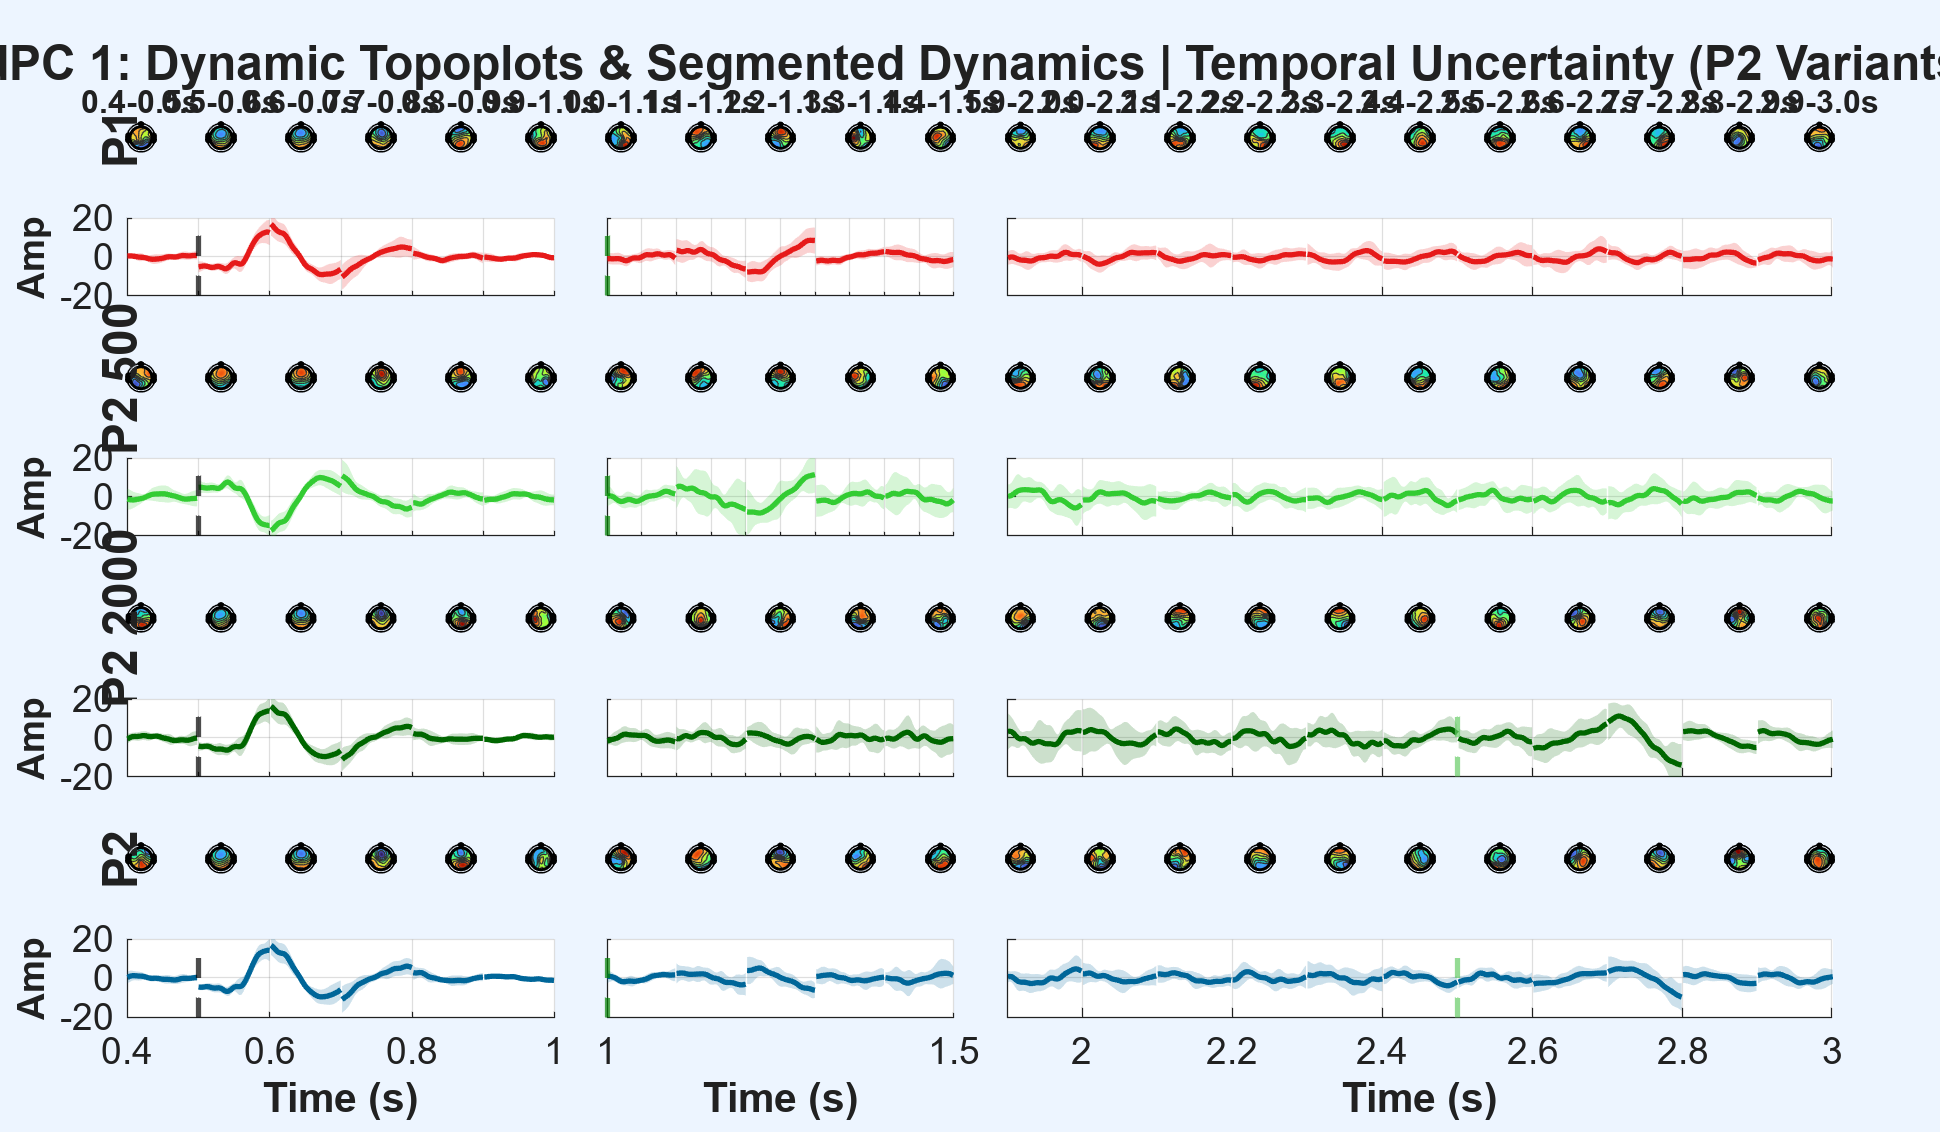

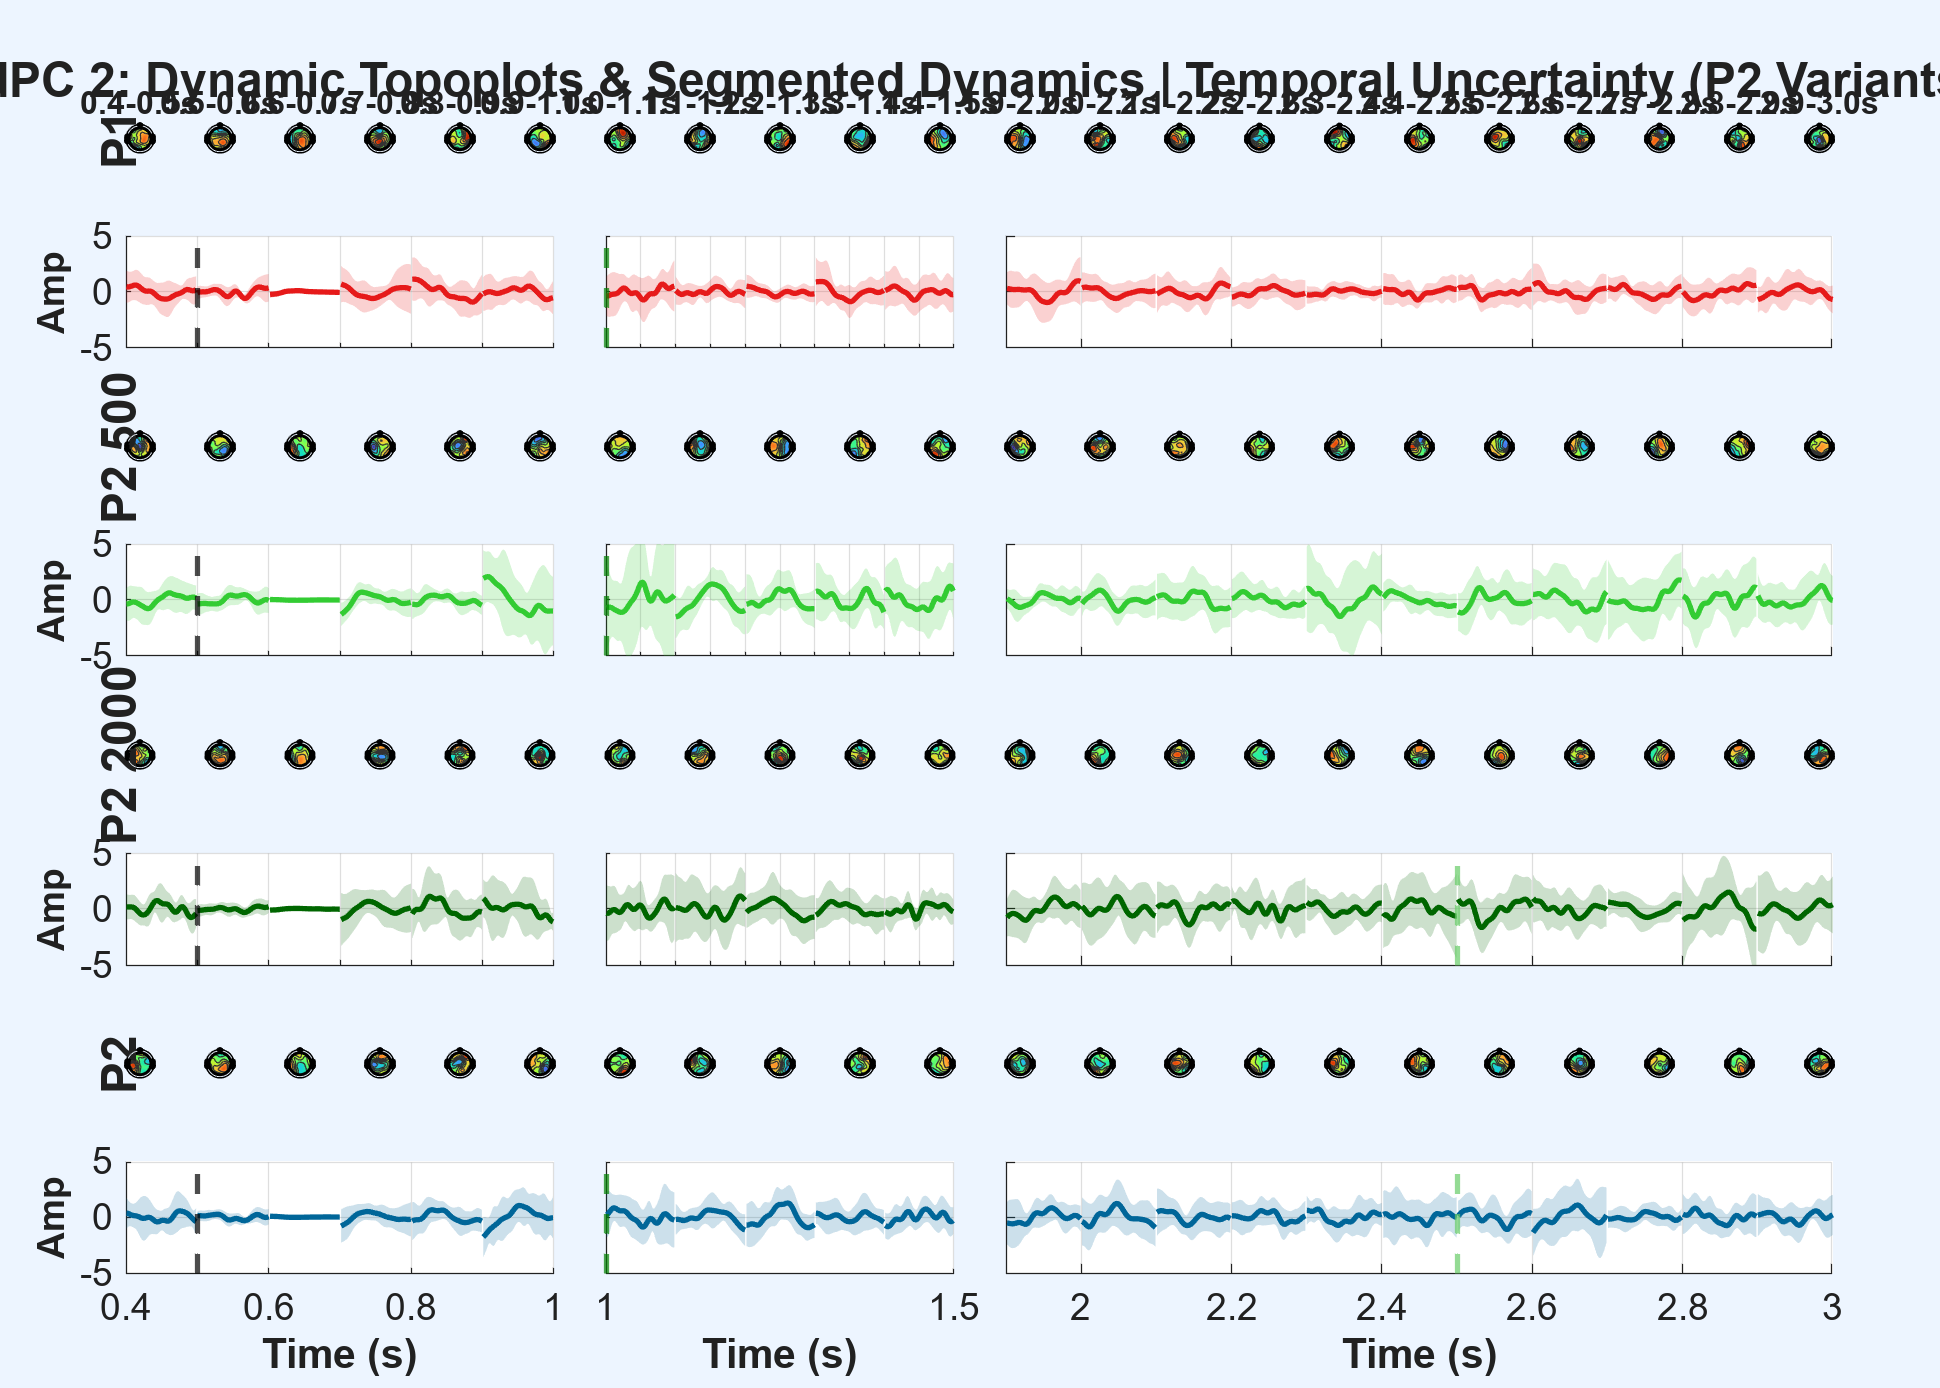

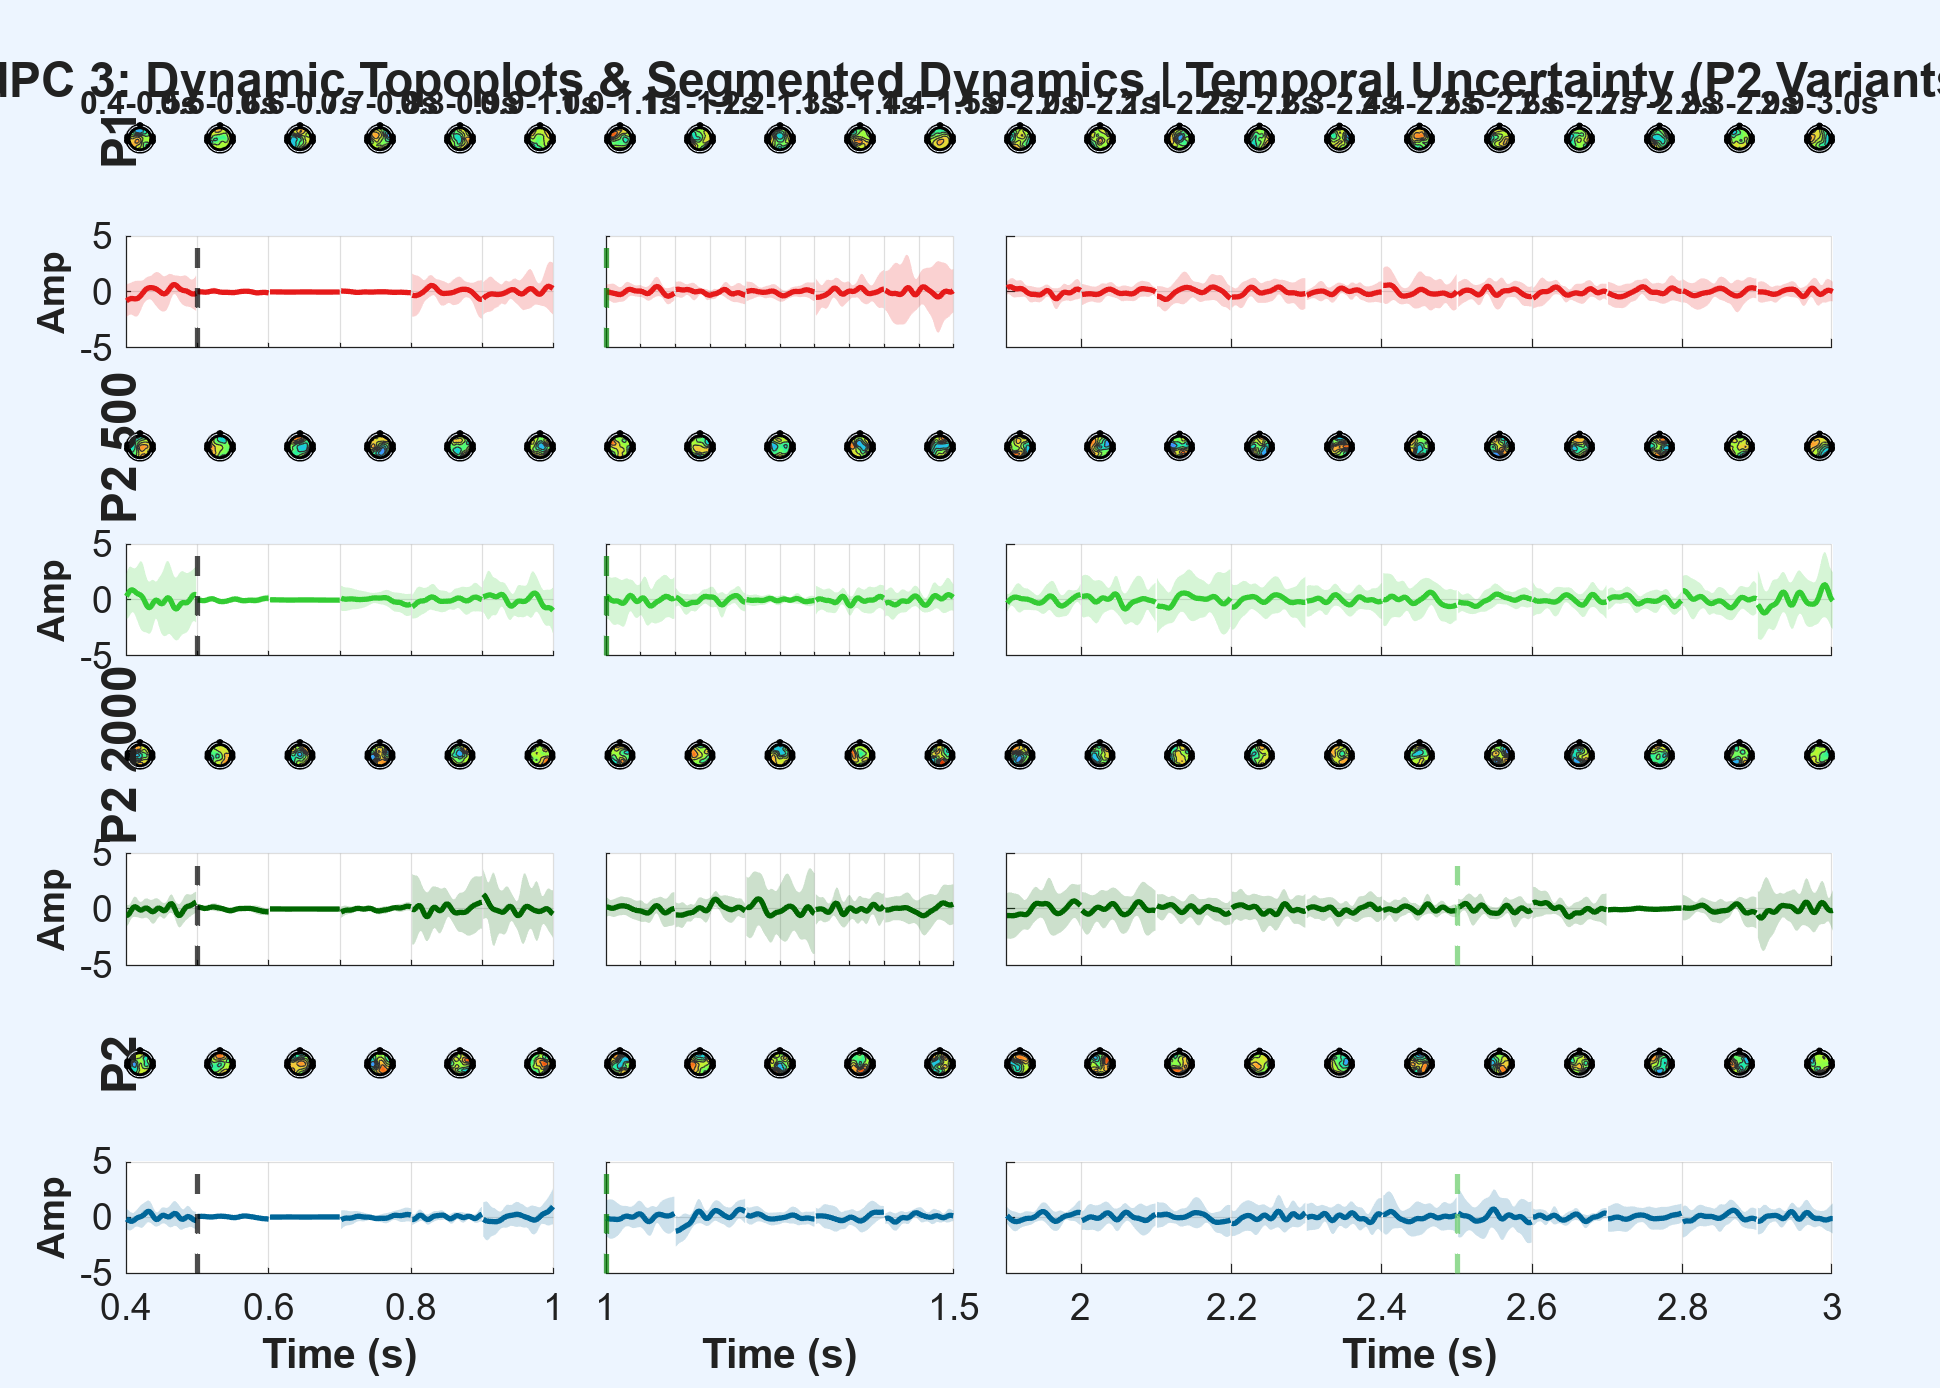

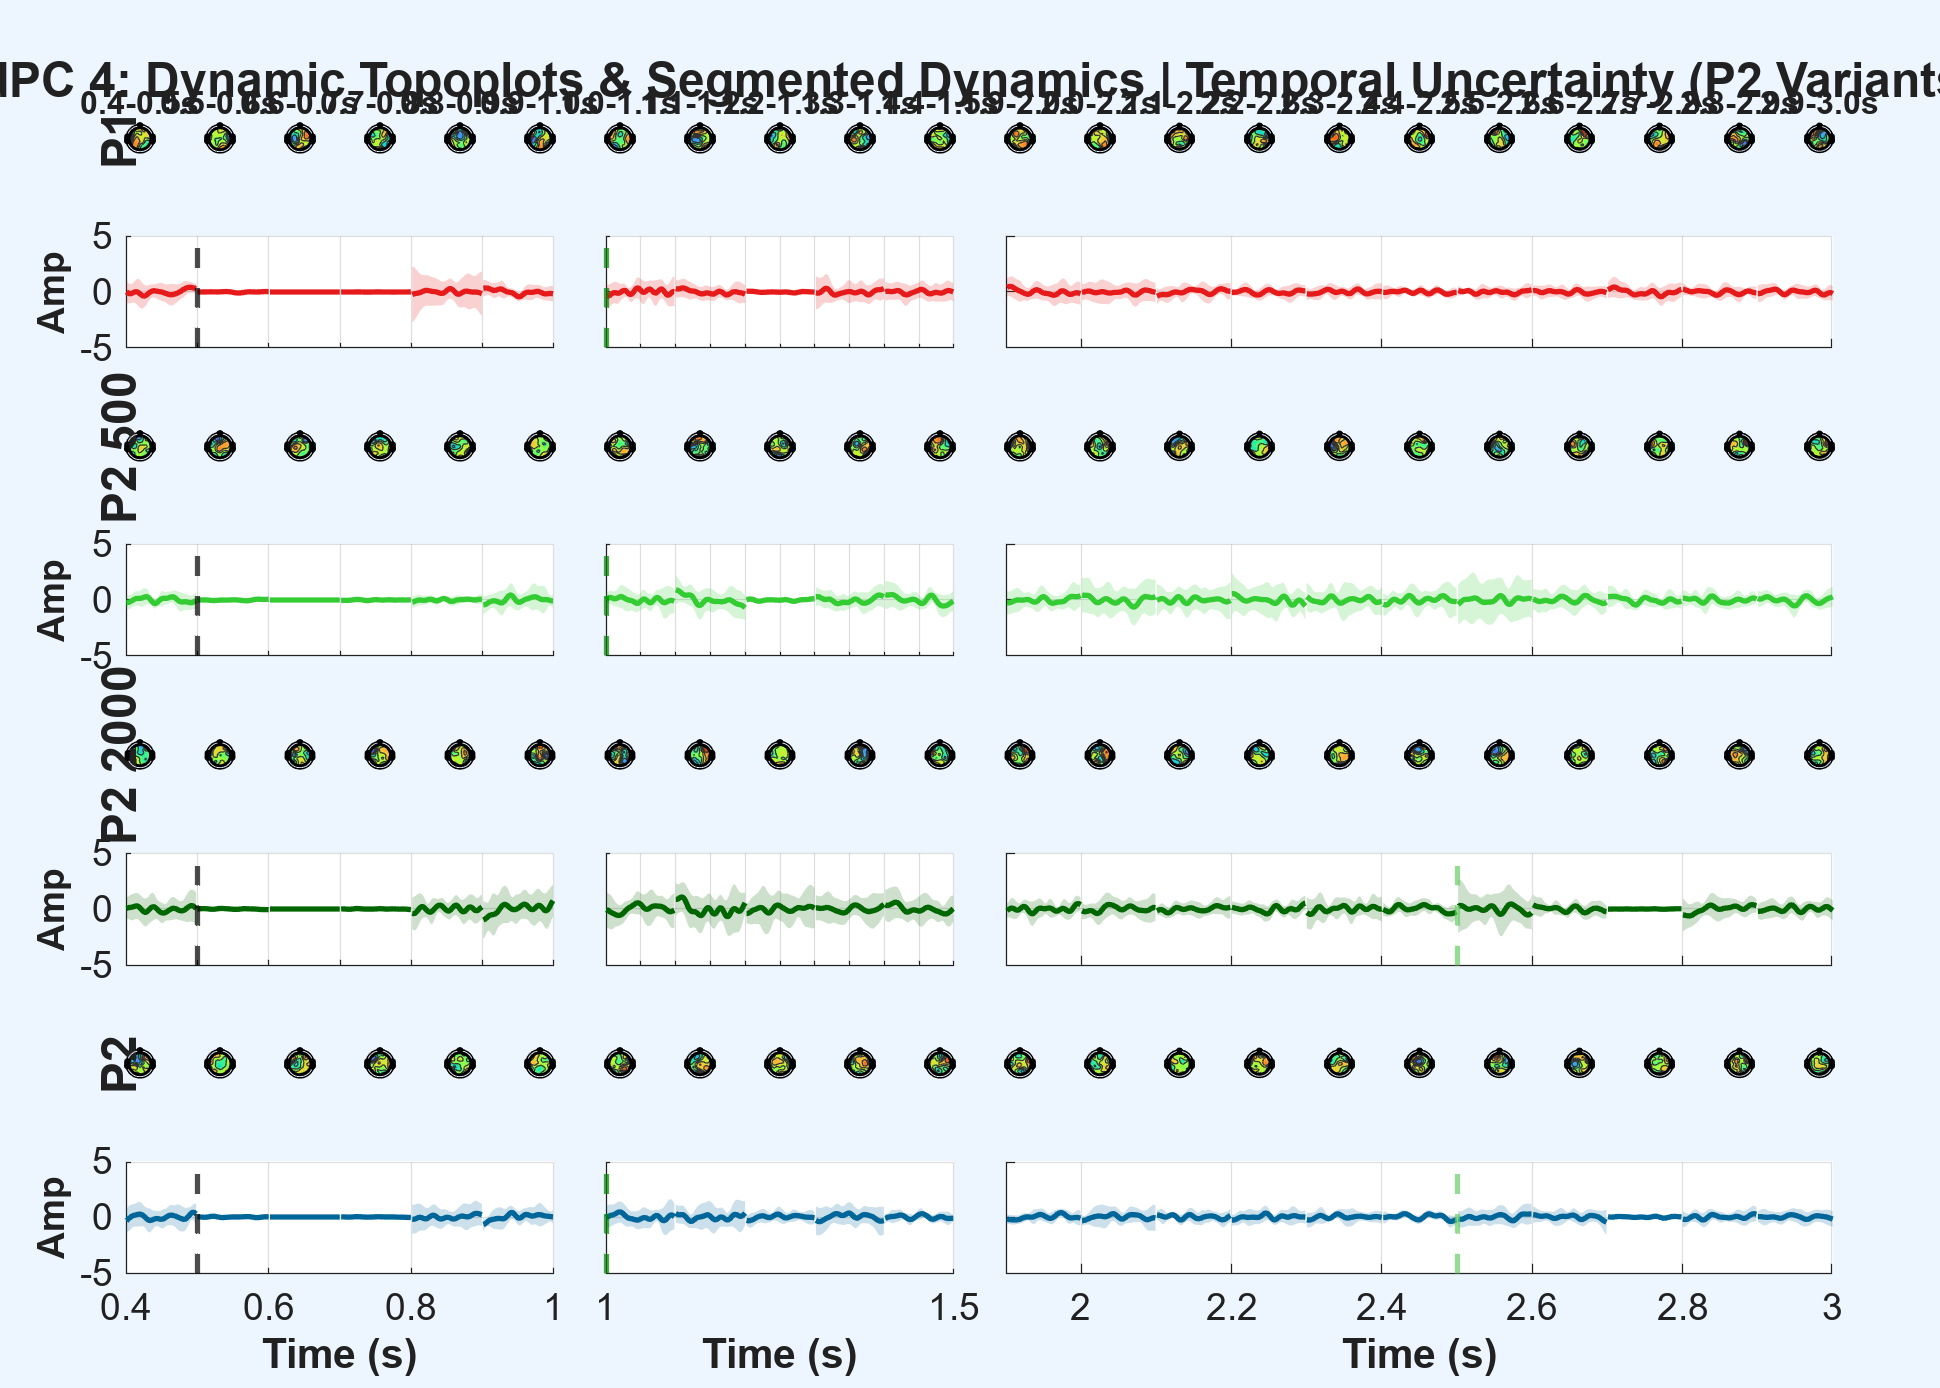

warning('off', 'all');

num_comps_plot = 4;
dark_green  = [0 0.5 0];
light_green = [0.4 0.8 0.4];

% Custom Colors
color_map = struct(...
    'BLA', [0.6 0.6 0.6], 'BLT', [0.0 0.0 0.0], 'P1',  [0.9 0.1 0.1], ...
    'P2', [0.0 0.4 0.6], 'P2_500', [0.2 0.8 0.2], 'P2_2000', [0.0 0.4 0.0], ...
    'P3', [0.9 0.8 0.5], 'P3_500', [1.0 0.5 0.0], 'P3_missing', [0.6 0.2 0.8] ...
);

plot_groups = {
    {'BLA', 'BLT', 'P1'},                                  
    {'P1', 'P2_500', 'P2_2000', 'P2'},                     
    {'P1', 'P3_500', 'P3_missing', 'P3'}                   
};

group_titles = {
    'Multisensory Integration (BLA, BLT, P1)',
    'Temporal Uncertainty (P2 Variants)',
    'Stimulus Uncertainty (P3 Variants)'
};

for g = 1:length(plot_groups)
    target_conds = plot_groups{g};
    num_conds = length(target_conds);
    
    % --- Configure the Split Axes (Macro-Windows) ---
    if g == 2 % Temporal Uncertainty requires the 3rd subplot
        macro_windows = {
            struct('cols', 1:6,   'xlim', [0.4 1.0], 'ylim', [-20 20]),
            struct('cols', 7:11,  'xlim', [1.0 1.5], 'ylim', [-10 10]),
            struct('cols', 12:22, 'xlim', [1.9 3.0], 'ylim', [-10 10])
        };
        num_cols = 22;
        plot_starts = [0.4:0.1:0.9, 1.0:0.1:1.4, 1.9:0.1:2.9];
        plot_ends   = [0.5:0.1:1.0, 1.1:0.1:1.5, 2.0:0.1:3.0];
    else % Group 1 and 3 only need the first two subplots
        macro_windows = {
            struct('cols', 1:6,  'xlim', [0.4 1.0], 'ylim', [-20 20]),
            struct('cols', 7:11, 'xlim', [1.0 1.5], 'ylim', [-10 10])
        };
        num_cols = 11;
        plot_starts = [0.4:0.1:0.9, 1.0:0.1:1.4];
        plot_ends   = [0.5:0.1:1.0, 1.1:0.1:1.5];
    end
    
    for pc = 1:num_comps_plot
        fig_name = sprintf('Dynamic dPCA Grid: Group %d - dPC %d', g, pc);
        figure('Position', [50, 50, 2400, 350 * num_conds], 'Name', fig_name);
        
        t = tiledlayout(num_conds * 2, num_cols, 'TileSpacing', 'tight', 'Padding', 'compact');
        title(t, sprintf('dPC %d: Dynamic Topoplots & Segmented Dynamics | %s', pc, group_titles{g}), ...
            'FontSize', 18, 'FontWeight', 'bold');
        
        for cond_idx = 1:num_conds
            c_name = target_conds{cond_idx};
            clean_name = strrep(c_name, '_', ' ');
            if ~isfield(dpca_dyn, c_name), continue; end
            
            num_subjects = length(data_all_conds.(c_name));
            if isfield(color_map, c_name), clr = color_map.(c_name); else, clr = [0 0 1]; end
            
            % Global Color Scale for Topoplots
            V_matrix = dpca_dyn.(c_name).V(:, pc, :);
            max_topo = max(abs(V_matrix(~isnan(V_matrix(:))))); 
            if isempty(max_topo) || max_topo == 0, max_topo = 1; end
            clim_bound = [-max_topo, max_topo] * 0.8;
            
            % ========================================================
            % ROW 1: PLOT 100ms TOPOPLOTS (1 Tile Each)
            % ========================================================
            for col = 1:num_cols
                t_start = plot_starts(col); t_end = plot_ends(col);
                t_center = (t_start + t_end) / 2;
                
                topo_tile_idx = (cond_idx - 1) * 2 * num_cols + col;
                nexttile(topo_tile_idx);
                
                [~, w_local] = min(abs(dpca_dyn.global_time_centers - t_center));
                master_encoder = dpca_dyn.(c_name).V(:, pc, w_local);
                
                if any(isnan(master_encoder))
                    axis off; continue; % Skip blank windows
                end
                
                topoplot(master_encoder, EEG.chanlocs, 'electrodes', 'off', 'maplimits', clim_bound);
                
                if cond_idx == 1 
                    title(sprintf('%.1f-%.1fs', t_start, t_end), 'FontSize', 12, 'FontWeight', 'bold');
                end
                if col == 1
                    text(-0.8, 0, clean_name, 'FontSize', 18, 'FontWeight', 'bold', 'Rotation', 90, 'HorizontalAlignment', 'center');
                end
            end
            
            % ========================================================
            % ROW 2: PLOT THE SPANNING TRACE SUBPLOTS
            % ========================================================
            for mw = 1:length(macro_windows)
                mw_info = macro_windows{mw};
                
                % Target the exact starting tile and span the needed columns
                trace_row_start = (cond_idx * 2 - 1) * num_cols;
                nexttile(trace_row_start + mw_info.cols(1), [1 length(mw_info.cols)]);
                hold on;
                
                for col = mw_info.cols
                    t_start = plot_starts(col); t_end = plot_ends(col);
                    t_center = (t_start + t_end) / 2;
                    
                    [~, w_local] = min(abs(dpca_dyn.global_time_centers - t_center));
                    master_decoder = dpca_dyn.(c_name).W(:, pc, w_local);
                    
                    if any(isnan(master_decoder)), continue; end
                    
                    idx = find(time_ms_eeg >= t_start & time_ms_eeg < t_end);
                    time_win = time_ms_eeg(idx);
                    all_subj_traces = zeros(length(time_win), num_subjects);
                    
                    for s = 1:num_subjects
                        subj_data = data_all_conds.(c_name){s}(:, idx, :);
                        subj_erp = mean(subj_data, 3, 'omitnan'); 
                        subj_mu = mean(subj_erp', 1);
                        all_subj_traces(:, s) = (subj_erp' - subj_mu) * master_decoder;
                    end
                    
                    trace_mean = mean(all_subj_traces, 2, 'omitnan')';
                    trace_std = std(all_subj_traces, 0, 2, 'omitnan')';
                    
                    % Shaded Ribbon & Mean Trace
                    x_patch = [time_win(:)', flip(time_win(:)')];
                    y_patch = [trace_mean + trace_std, flip(trace_mean - trace_std)];
                    patch(x_patch, y_patch, clr, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
                    plot(time_win, trace_mean, 'Color', clr, 'LineWidth', 2);
                end
                
                % --- Event Lines ---
                if mw == 1 % 0.4 to 1.0s window
                    xline(0.5, 'k--', 'LineWidth', 2);
                elseif mw == 2 % 1.0 to 1.5s window
                    if strcmp(c_name, 'P3_missing')
                        xline(1.0, 'r:', 'LineWidth', 2);
                    elseif ismember(c_name, {'BLT', 'P1', 'P2_500', 'P2', 'P3_500', 'P3'})
                        xline(1.0, '--', 'Color', dark_green, 'LineWidth', 2);
                    end
                elseif mw == 3 % 1.9 to 3.0s window
                    if ismember(c_name, {'P2_2000', 'P2'})
                        xline(2.5, '--', 'Color', light_green, 'LineWidth', 2);
                    end
                end
                
                hold off;
                
                % --- Explicit Bounds & Formatting ---
                xlim(mw_info.xlim);
                
                % --- NEW: DYNAMIC Y-LIMITS BASED ON PC ---
                if pc == 1
                    current_ylim = mw_info.ylim; % Use default [-20 20] or [-10 10]
                else
                    current_ylim = [-5 5];       % Zoom in tight for dPC 2-4
                end
                
                ylim(current_ylim);
                yticks([current_ylim(1), 0, current_ylim(2)]); % Hardcode ticks for exact scales
                grid on;
                
                if cond_idx == num_conds
                    xlabel('Time (s)', 'FontSize', 16, 'FontWeight', 'bold');
                else
                    xticklabels({});
                end
                
                set(gca, 'FontSize', 14);
                
                % Only show Y-label on the very first trace column
                if mw == 1
                    ylabel('Amp', 'FontSize', 14, 'FontWeight', 'bold');
                else
                    yticklabels({});
                end
            end
            
        end
    end
end

warning('on', 'all');
disp('Segmented Dynamic dPCA visualization complete.');

Segmented Dynamic dPCA visualization complete.


## 4.0 Statistical Quantification: RM ANOVA & Bar Charts on dPC Amplitudes


disp('Running RM ANOVA and Generating Statistical Bar Charts (Normalized AUC)...');

num_comps_stat = 2; % Test top 2 dPCs

% Helper to guarantee MATLAB-safe table variable names
clean_var_name = @(name) matlab.lang.makeValidName(strrep(name, '_', ''));
get_clean_name = @(x) strrep(strrep(strrep(strrep(strrep(strrep(strrep(strrep(strrep(x, ...
    'P2_500', 'Unpred. 500'), 'P2_2000', 'Unpred. 2000'), 'P3_500', 'Rand. Cued 500'), ...
    'P3_missing', 'Rand. Missing'), 'BLA', 'Auditory'), 'BLT', 'Tactile'), ...
    'P1', 'Cued'), 'P2', 'Unpred.'), 'P3', 'Rand. Cued');

color_map = struct('BLA', [0.6 0.6 0.6], 'BLT', [0.0 0.0 0.0], 'P1', [0.9 0.1 0.1], ...
    'P2', [0.0 0.4 0.6], 'P2_500', [0.2 0.8 0.2], 'P2_2000', [0.0 0.4 0.0], ...
    'P3', [0.9 0.8 0.5], 'P3_500', [1.0 0.5 0.0], 'P3_missing', [0.6 0.2 0.8]);

for m = 1:length(model_names)
    m_name = model_names{m};
    conds = dpca_configs.(m_name);
    num_c = length(conds);
    
    fprintf('\n======================================================\n');
    fprintf('  ANOVA RESULTS FOR SPACE: %s\n', m_name);
    fprintf('======================================================\n');
    
    for pc = 1:num_comps_stat
        fprintf('\n--- Analyzing dPC %d ---\n', pc);
        
        num_subjs = length(data_all_conds.(conds{1})); 
        anova_data = zeros(num_subjs, num_c * 2); 
        varNames = cell(1, num_c * 2);
        cond_factors = cell(num_c * 2, 1);
        win_factors  = cell(num_c * 2, 1);
        col_idx = 1;
        
        for c = 1:num_c
            c_name = conds{c};
            
            if strcmp(m_name, 'Temp')
                win_sensory   = [0.50 0.85; 1.00 1.35; 2.50 2.85];
                win_cognitive = [0.85 1.00; 1.35 1.50; 2.50 2.85; 2.85 3.00]; 
            else
                win_sensory   = [0.50 0.85];
                win_cognitive = [0.85 1.00];
            end
            
            for s = 1:num_subjs
                % --- NEW: Project using the LOSO decoder specific to this subject ---
                master_decoder = dpca_models.(m_name).loso(s).W(:, pc);
                mu_s           = dpca_models.(m_name).loso(s).mu;
                
                subj_data = mean(data_all_conds.(c_name){s}, 3, 'omitnan');
                subj_trace = master_decoder' * (subj_data - mu_s);
                
                % --- INLINE FUNCTION: Time-Normalized Absolute AUC ---
                % Compute Sensory AUC
                tot_area = 0; tot_time = 0;
                for w_i = 1:size(win_sensory, 1)
                    idx = find(time_ms_eeg >= win_sensory(w_i,1) & time_ms_eeg <= win_sensory(w_i,2));
                    if length(idx) > 1
                        t_sub = time_ms_eeg(idx); tr_sub = abs(subj_trace(idx));
                        valid = ~isnan(tr_sub);
                        if sum(valid) > 1
                            tot_area = tot_area + trapz(t_sub(valid), tr_sub(valid));
                            tot_time = tot_time + (t_sub(find(valid, 1, 'last')) - t_sub(find(valid, 1, 'first')));
                        end
                    end
                end
                anova_data(s, col_idx) = tot_area / max(tot_time, eps); % Avoid div 0
                
                % Compute Cognitive AUC
                tot_area = 0; tot_time = 0;
                for w_i = 1:size(win_cognitive, 1)
                    idx = find(time_ms_eeg >= win_cognitive(w_i,1) & time_ms_eeg <= win_cognitive(w_i,2));
                    if length(idx) > 1
                        t_sub = time_ms_eeg(idx); tr_sub = abs(subj_trace(idx));
                        valid = ~isnan(tr_sub);
                        if sum(valid) > 1
                            tot_area = tot_area + trapz(t_sub(valid), tr_sub(valid));
                            tot_time = tot_time + (t_sub(find(valid, 1, 'last')) - t_sub(find(valid, 1, 'first')));
                        end
                    end
                end
                anova_data(s, col_idx + 1) = tot_area / max(tot_time, eps);
            end
            
            safe_c_name = clean_var_name(c_name);
            varNames{col_idx} = sprintf('%s_Sens', safe_c_name); varNames{col_idx + 1} = sprintf('%s_Cog', safe_c_name);
            cond_factors{col_idx} = c_name; cond_factors{col_idx + 1} = c_name;
            win_factors{col_idx} = 'Sensory'; win_factors{col_idx + 1} = 'Cognitive';
            col_idx = col_idx + 2;
        end
        
        % --- Build Table and Run ANOVA ---
        tbl = array2table(anova_data, 'VariableNames', varNames);
        Condition = categorical(cond_factors); Window = categorical(win_factors);
        withinTbl = table(Condition, Window);
        
        try
            rm = fitrm(tbl, sprintf('%s-%s ~ 1', varNames{1}, varNames{end}), 'WithinDesign', withinTbl);
            ranovatbl = ranova(rm, 'WithinModel', 'Condition*Window');
            disp(ranovatbl);
            
            pval_cond = ranovatbl.pValue(2); pval_win  = ranovatbl.pValue(4); pval_int  = ranovatbl.pValue(6);
            
            % --- PLOTTING ---
            figure('Position', [100 + (m*30), 100 + (pc*30), 900, 600], 'Name', sprintf('ANOVA: %s Space - dPC %d', m_name, pc));
            plot_means = zeros(2, num_c); plot_sems  = zeros(2, num_c); legend_names = cell(1, num_c);
            
            for c = 1:num_c
                c_sens_col = (c-1)*2 + 1; c_cog_col  = (c-1)*2 + 2;
                plot_means(1, c) = mean(anova_data(:, c_sens_col)); plot_means(2, c) = mean(anova_data(:, c_cog_col));
                plot_sems(1, c) = std(anova_data(:, c_sens_col)) / sqrt(num_subjs); plot_sems(2, c) = std(anova_data(:, c_cog_col)) / sqrt(num_subjs);
                legend_names{c} = get_clean_name(conds{c});
            end
            
            b = bar(plot_means, 'grouped'); hold on;
            for c = 1:num_c
                if isfield(color_map, conds{c}), b(c).FaceColor = color_map.(conds{c}); end
                errorbar(b(c).XEndPoints, plot_means(:, c), plot_sems(:, c), 'k', 'linestyle', 'none', 'LineWidth', 1.5, 'CapSize', 8);
            end
            hold off;
            
            set(gca, 'XTick', [1 2], 'XTickLabel', {'Sensory Window', 'Cognitive Window'}, 'FontSize', 14);
            ylabel('Normalized AUC (\pm SEM)', 'FontSize', 16, 'FontWeight', 'bold');
            title(sprintf('%s: dPC %d Amplitude (Norm. AUC)', m_name, pc), 'FontSize', 20, 'FontWeight', 'bold'); grid on;
            legend(b, legend_names, 'Location', 'best', 'FontSize', 12);
            
            stat_str = {'Repeated Measures ANOVA', '-------------------------------', ...
                sprintf('Condition Effect:  p = %.4f %s', pval_cond, get_sig_star(pval_cond)), ...
                sprintf('Window Effect:     p = %.4f %s', pval_win, get_sig_star(pval_win)), ...
                sprintf('Interaction (C x W): p = %.4f %s', pval_int, get_sig_star(pval_int))};
            annotation('textbox', [0.15 0.75 0.3 0.15], 'String', stat_str, 'FitBoxToText', 'on', 'BackgroundColor', 'w', 'EdgeColor', 'k', 'FontSize', 12, 'FontWeight', 'bold', 'Interpreter', 'none');
        catch ME
            fprintf('Error running ANOVA for %s dPC %d.\n', m_name, pc); disp(ME.message);
        end
    end
end

Running Repeated Measures ANOVA (Condition x Time Window) on dPC amplitudes...


  ANOVA RESULTS FOR SPACE: MS


  Conditions tested: BLA, BLT, P1



--- Analyzing dPC 1 ---


                                    SumSq     DF    MeanSq       F        pValue      pValueGG     pValueHF     pValueLB 
                                    ______    __    ______    _______    _________    _________    _________    _________
    (Intercept)                      73.25     1     73.25     12.529    0.0036273    0.0036273    0.0036273    0.0036273
    Error                           76.001    13    5.8462                                                               
    (Intercept):Condition           4.0479     2     2.024    0.49888      0.61291      0.59175      0.61291      0.49246
    Error(Condition)                105.48    26  

--- No significant interaction (p = 0.5000). The differences between conditions are stable across time. ---



--- Analyzing dPC 2 ---


                                    SumSq     DF    MeanSq      F        pValue      pValueGG     pValueHF     pValueLB
                                    ______    __    ______    ______    _________    _________    _________    ________
    (Intercept)                      4.495     1     4.495    1.2426      0.28516      0.28516      0.28516     0.28516
    Error                           47.028    13    3.6175                                                             
    (Intercept):Condition           31.591     2    15.795    6.0381    0.0070171    0.0081048    0.0070171    0.028817
    Error(Condition)                68.014    26    2.6159  

--- No significant interaction (p = 0.5000). The differences between conditions are stable across time. ---



--- Analyzing dPC 3 ---


                                     SumSq     DF    MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                                    _______    __    _______    _______    __________    __________    __________    __________
    (Intercept)                      64.323     1     64.323     61.552    2.7666e-06    2.7666e-06    2.7666e-06    2.7666e-06
    Error                            13.585    13      1.045                                                                   
    (Intercept):Condition           0.93875     2    0.46937    0.27353       0.76285       0.75699       0.76285       0.60977
    Error(Condition)         

--- No significant interaction (p = 0.5000). The differences between conditions are stable across time. ---



--- Analyzing dPC 4 ---


                                     SumSq      DF     MeanSq         F         pValue     pValueGG    pValueHF    pValueLB
                                    ________    __    ________    _________    ________    ________    ________    ________
    (Intercept)                     0.015953     1    0.015953    0.0044723      0.9477      0.9477      0.9477      0.9477
    Error                             46.372    13      3.5671                                                             
    (Intercept):Condition             27.581     2       13.79       3.2574    0.054649    0.062299    0.054649    0.094304
    Error(Condition)                  11

--- No significant interaction (p = 0.5000). The differences between conditions are stable across time. ---


  ANOVA RESULTS FOR SPACE: Temp


  Conditions tested: P1, P2_500, P2_2000, P2



--- Analyzing dPC 1 ---


                                     SumSq     DF     MeanSq          F         pValue      pValueGG     pValueHF     pValueLB 
                                    _______    __    _________    _________    _________    _________    _________    _________
    (Intercept)                      1.5917     1       1.5917      0.69819      0.41849      0.41849      0.41849      0.41849
    Error                            29.636    13       2.2797                                                                 
    (Intercept):Condition            3.5701     3         1.19      0.65249      0.58621      0.48761      0.50056      0.43376
    Error(Condition)         

--- No significant interaction (p = 0.5000). The differences between conditions are stable across time. ---



--- Analyzing dPC 2 ---


                                     SumSq      DF     MeanSq        F        pValue     pValueGG    pValueHF    pValueLB
                                    ________    __    ________    ________    _______    ________    ________    ________
    (Intercept)                      0.13431     1     0.13431     0.30447    0.59045    0.59045     0.59045     0.59045 
    Error                             5.7345    13     0.44111                                                           
    (Intercept):Condition             3.6331     3       1.211      0.8467    0.47676    0.39857     0.40432     0.37425 
    Error(Condition)                  55.781    39

--- No significant interaction (p = 0.5000). The differences between conditions are stable across time. ---



--- Analyzing dPC 3 ---


                                     SumSq     DF     MeanSq        F        pValue      pValueGG     pValueHF     pValueLB 
                                    _______    __    ________    _______    _________    _________    _________    _________
    (Intercept)                       1.827     1       1.827     1.1855      0.29601      0.29601      0.29601      0.29601
    Error                            20.034    13      1.5411                                                               
    (Intercept):Condition            2.1404     3     0.71345    0.17602      0.91199      0.71156       0.7188      0.68166
    Error(Condition)               

--- No significant interaction (p = 0.5000). The differences between conditions are stable across time. ---



--- Analyzing dPC 4 ---


                                      SumSq      DF     MeanSq          F          pValue     pValueGG    pValueHF    pValueLB
                                    _________    __    _________    __________    ________    ________    ________    ________
    (Intercept)                     0.0003263     1    0.0003263    0.00055983     0.98148    0.98148     0.98148     0.98148 
    Error                              7.5771    13      0.58285                                                              
    (Intercept):Condition               1.311     3      0.43701       0.13068     0.94127    0.75402     0.76135     0.72353 
    Error(Condition)            </

--- No significant interaction (p = 0.5000). The differences between conditions are stable across time. ---


  ANOVA RESULTS FOR SPACE: Stim


  Conditions tested: P1, P3_500, P3_missing, P3



--- Analyzing dPC 1 ---


                                    SumSq     DF    MeanSq       F         pValue      pValueGG     pValueHF     pValueLB 
                                    ______    __    ______    ________    _________    _________    _________    _________
    (Intercept)                     17.609     1    17.609      0.1604      0.69529      0.69529      0.69529      0.69529
    Error                           1427.2    13    109.78                                                                
    (Intercept):Condition           5.1266     3    1.7089    0.097421      0.96099      0.82614      0.84085       0.7599
    Error(Condition)                684.11   

--- No significant interaction (p = 0.5000). The differences between conditions are stable across time. ---



--- Analyzing dPC 2 ---


                                     SumSq     DF    MeanSq        F        pValue      pValueGG     pValueHF     pValueLB 
                                    _______    __    _______    _______    _________    _________    _________    _________
    (Intercept)                      529.64     1     529.64     12.062    0.0041217    0.0041217    0.0041217    0.0041217
    Error                            570.82    13     43.909                                                               
    (Intercept):Condition             2.471     3    0.82365    0.12619      0.94404      0.81677      0.83614      0.72812
    Error(Condition)                 254

--- No significant interaction (p = 0.5000). The differences between conditions are stable across time. ---



--- Analyzing dPC 3 ---


                                    SumSq     DF    MeanSq       F       pValue     pValueGG    pValueHF    pValueLB
                                    ______    __    ______    _______    _______    ________    ________    ________
    (Intercept)                     2.1413     1    2.1413    0.23052    0.63912    0.63912     0.63912     0.63912 
    Error                           120.76    13    9.2889                                                          
    (Intercept):Condition           86.915     3    28.972     0.5257    0.66721    0.50496     0.51077     0.48127 
    Error(Condition)                2149.3    39     55.11                 

--- No significant interaction (p = 0.5000). The differences between conditions are stable across time. ---



--- Analyzing dPC 4 ---


                                     SumSq     DF    MeanSq        F        pValue     pValueGG    pValueHF    pValueLB
                                    _______    __    _______    ________    _______    ________    ________    ________
    (Intercept)                      1.4497     1     1.4497    0.021848    0.88476    0.88476     0.88476     0.88476 
    Error                            862.61    13     66.355                                                           
    (Intercept):Condition             361.6     3     120.53      1.4349    0.24728    0.25279      0.2529     0.25235 
    Error(Condition)                   3276    39     84.001

--- No significant interaction (p = 0.5000). The differences between conditions are stable across time. ---


disp('Statistical quantification complete.');

Statistical quantification complete.


## 5.0 Statistical Quantification: RM ANOVA & Bar Charts on dPC Amplitudes

%% 5.0 Statistical Quantification: RM ANOVA & Bar Charts on Latent Trajectory Similarity
disp('Running RM ANOVA on Latent Trajectory Cosine Similarity (LOSO)...');

Running RM ANOVA on Latent Trajectory Cosine Similarity (LOSO)...


  ANOVA RESULTS FOR SPACE: MS (dPC1 Trajectories)


                                SumSq      DF     MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                               ________    __    ________    _______    __________    __________    __________    __________
    (Intercept)                   15.86     1       15.86     158.18    1.1876e-08    1.1876e-08    1.1876e-08    1.1876e-08
    Error                        1.3035    13     0.10027                                                                   
    (Intercept):Pair             1.5616     1      1.5616     18.782    0.00081093    0.00081093    0.00081093    0.00081093
    Error(Pair)                  1.

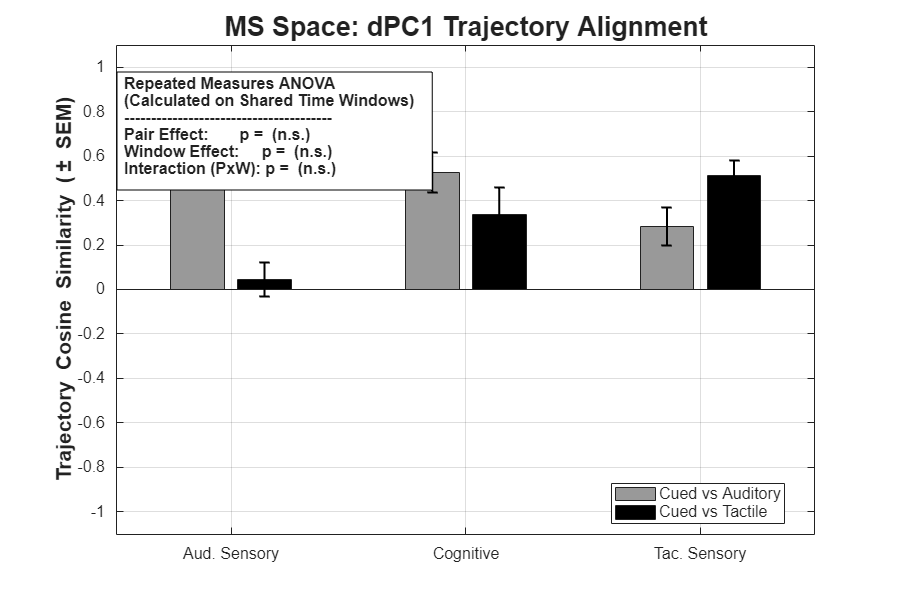

  ANOVA RESULTS FOR SPACE: Temp (dPC1 Trajectories)


                                SumSq     DF      MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                               _______    ___    ________    ______    __________    __________    __________    __________
    (Intercept)                 29.722      1      29.722    92.382    2.8437e-07    2.8437e-07    2.8437e-07    2.8437e-07
    Error                       4.1825     13     0.32173                                                                  
    (Intercept):Pair           0.37147      2     0.18574    4.6249      0.019125      0.042554      0.040543      0.050903
    Error(Pair)                 1.0441  

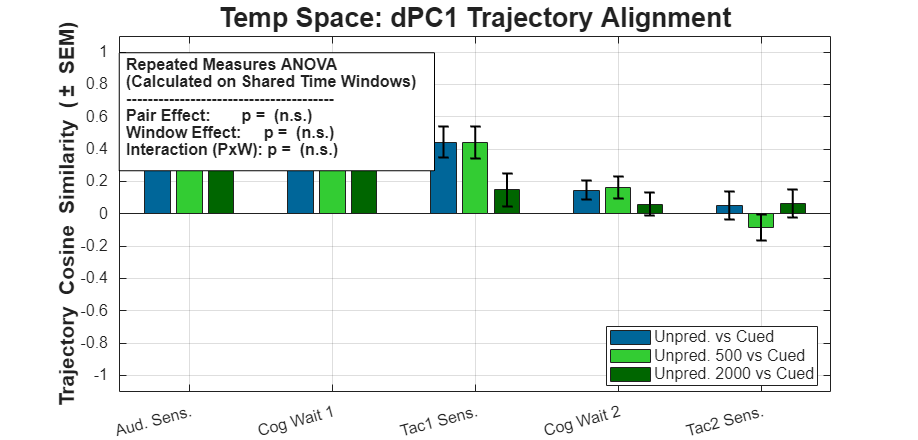

  ANOVA RESULTS FOR SPACE: Stim (dPC1 Trajectories)


                                SumSq     DF     MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                               _______    __    ________    _______    __________    __________    __________    __________
    (Intercept)                 36.854     1      36.854     43.584    1.7105e-05    1.7105e-05    1.7105e-05    1.7105e-05
    Error                       10.993    13     0.84558                                                                   
    (Intercept):Pair           0.18749     2    0.093746    0.67997       0.51541       0.44047       0.44439       0.42447
    Error(Pair)                 3.5845  

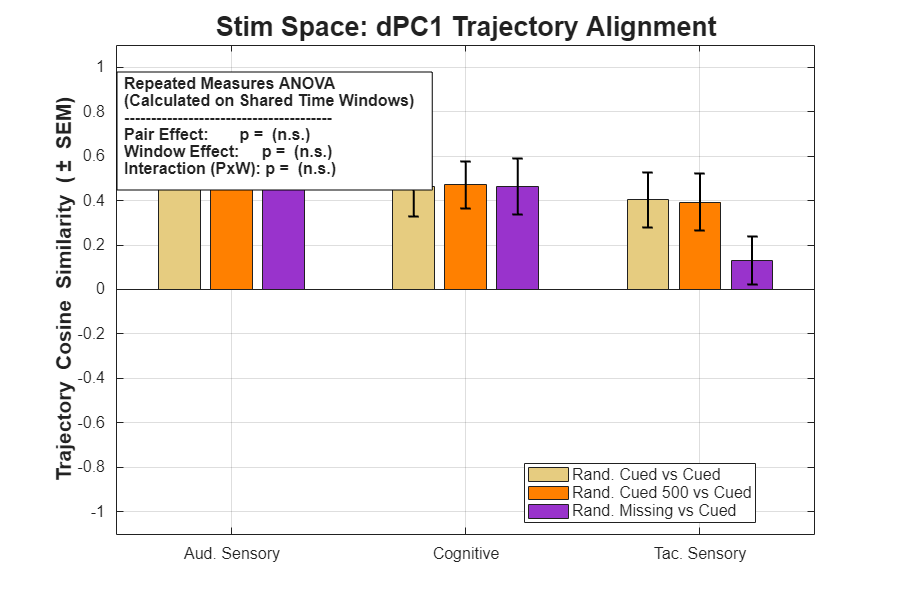

warning('off', 'all');

num_comps_sim = 1; % Lock strictly to dPC1

clean_var_name = @(name) matlab.lang.makeValidName(strrep(name, '_', ''));
get_clean_name = @(x) strrep(strrep(strrep(strrep(strrep(strrep(strrep(strrep(strrep(x, ...
    'P2_500', 'Unpred. 500'), 'P2_2000', 'Unpred. 2000'), 'P3_500', 'Rand. Cued 500'), ...
    'P3_missing', 'Rand. Missing'), 'BLA', 'Auditory'), 'BLT', 'Tactile'), ...
    'P1', 'Cued'), 'P2', 'Unpred.'), 'P3', 'Rand. Cued');

color_map = struct('BLA', [0.6 0.6 0.6], 'BLT', [0.0 0.0 0.0], 'P1', [0.9 0.1 0.1], ...
    'P2', [0.0 0.4 0.6], 'P2_500', [0.2 0.8 0.2], 'P2_2000', [0.0 0.4 0.0], ...
    'P3', [0.9 0.8 0.5], 'P3_500', [1.0 0.5 0.0], 'P3_missing', [0.6 0.2 0.8]);

stat_groups = {
    {'MS', {'P1', 'BLA'; 'P1', 'BLT'}, [0.50 0.85; 0.85 1.00; 1.00 1.35], {'Aud. Sensory', 'Cognitive', 'Tac. Sensory'}}, ...
    {'Temp', {'P2', 'P1'; 'P2_500', 'P1'; 'P2_2000', 'P1'}, [0.50 0.85; 0.85 1.00; 1.00 1.35; 1.35 2.50; 2.50 2.85], {'Aud. Sens.', 'Cog Wait 1', 'Tac1 Sens.', 'Cog Wait 2', 'Tac2 Sens.'}}, ...
    {'Stim', {'P3', 'P1'; 'P3_500', 'P1'; 'P3_missing', 'P1'}, [0.50 0.85; 0.85 1.00; 1.00 1.35], {'Aud. Sensory', 'Cognitive', 'Tac. Sensory'}}
};

for g = 1:length(stat_groups)
    m_name = stat_groups{g}{1}; pairs = stat_groups{g}{2};
    win_bounds = stat_groups{g}{3}; win_labels = stat_groups{g}{4};
    
    num_pairs = size(pairs, 1); num_windows = size(win_bounds, 1);
    num_subjs = length(data_all_conds.(pairs{1,1}));
    
    fprintf('\n======================================================\n');
    fprintf('  ANOVA RESULTS FOR SPACE: %s (dPC1 Trajectories)\n', m_name);
    fprintf('======================================================\n');
    
    anova_data = nan(num_subjs, num_pairs * num_windows); 
    varNames = cell(1, num_pairs * num_windows);
    pair_factors = cell(num_pairs * num_windows, 1); win_factors = cell(num_pairs * num_windows, 1);
    
    col_idx = 1;
    for p = 1:num_pairs
        cond_A = pairs{p, 1}; cond_B = pairs{p, 2};
        for w = 1:num_windows
            t_start = win_bounds(w, 1); t_end = win_bounds(w, 2);
            idx_win = find(time_ms_eeg >= t_start & time_ms_eeg <= t_end);
            
            for s = 1:num_subjs
                % --- NEW: Use LOSO decoder to extract clean 1D trajectories ---
                master_W = dpca_models.(m_name).loso(s).W(:, num_comps_sim);
                mu_s     = dpca_models.(m_name).loso(s).mu;
                
                data_A = mean(data_all_conds.(cond_A){s}, 3, 'omitnan');
                data_B = mean(data_all_conds.(cond_B){s}, 3, 'omitnan');
                
                % Check for early condition termination
                if all(isnan(data_A(1, idx_win))) || all(isnan(data_B(1, idx_win))), continue; end
                
                % Project raw data through LOSO manifold
                proj_A = master_W' * (data_A - mu_s);
                proj_B = master_W' * (data_B - mu_s);
                
                % Extract targeted window vector
                x = proj_A(idx_win);
                y = proj_B(idx_win);
                
                valid = ~isnan(x) & ~isnan(y);
                if sum(valid) > 1
                    x_v = x(valid); y_v = y(valid);
                    % Real 1D Vector Cosine Similarity
                    anova_data(s, col_idx) = dot(x_v, y_v) / (norm(x_v) * norm(y_v));
                end
            end
            varNames{col_idx} = clean_var_name(sprintf('P%d_W%d', p, w));
            pair_factors{col_idx} = sprintf('%s vs %s', get_clean_name(cond_A), get_clean_name(cond_B));
            win_factors{col_idx} = win_labels{w};
            col_idx = col_idx + 1;
        end
    end
    
    % Dynamic Missing Data Filter for RM ANOVA
    valid_cols = ~any(isnan(anova_data), 1);
    anova_data_bal = anova_data(:, valid_cols);
    
    if isempty(anova_data_bal) || size(anova_data_bal, 2) < 2
        disp('Insufficient valid data to run ANOVA for this group.'); continue;
    end
    
    tbl = array2table(anova_data_bal, 'VariableNames', varNames(valid_cols));
    Pair = categorical(pair_factors(valid_cols)); Window = categorical(win_factors(valid_cols));
    withinTbl = table(Pair, Window);
    model_spec = sprintf('%s-%s ~ 1', varNames{find(valid_cols, 1, 'first')}, varNames{find(valid_cols, 1, 'last')});
    
    try
        rm = fitrm(tbl, model_spec, 'WithinDesign', withinTbl);
        ranovatbl = ranova(rm, 'WithinModel', 'Pair*Window'); disp(ranovatbl);
        rn = ranovatbl.Properties.RowNames;
        pval_pair = ranovatbl.pValue(strcmp(rn, 'Pair')); pval_win = ranovatbl.pValue(strcmp(rn, 'Window')); pval_int = ranovatbl.pValue(strcmp(rn, 'Pair:Window'));
    catch ME
        fprintf('Error running ANOVA for %s Space.\n', m_name); disp(ME.message);
        pval_pair = NaN; pval_win = NaN; pval_int = NaN;
    end
    
    % --- CREATE BAR CHART FIGURE ---
    figure('Position', [100 + (g*30), 100 + (g*30), max(900, num_windows*250), 600], 'Name', sprintf('ANOVA: %s Trajectory Similarity', m_name));
    plot_means = zeros(num_windows, num_pairs); plot_sems  = zeros(num_windows, num_pairs); legend_names = cell(1, num_pairs);
    
    for p = 1:num_pairs
        for w = 1:num_windows
            col = (p-1)*num_windows + w;
            plot_means(w, p) = mean(anova_data(:, col), 'omitnan');
            plot_sems(w, p)  = std(anova_data(:, col), 'omitnan') / sqrt(num_subjs);
        end
        legend_names{p} = sprintf('%s vs %s', get_clean_name(pairs{p,1}), get_clean_name(pairs{p,2}));
    end
    
    b = bar(plot_means, 'grouped'); hold on;
    for p = 1:num_pairs
        t_cond = pairs{p, 1}; if strcmp(t_cond, 'P1'), t_cond = pairs{p, 2}; end 
        if isfield(color_map, t_cond), b(p).FaceColor = color_map.(t_cond); end
        errorbar(b(p).XEndPoints, plot_means(:, p), plot_sems(:, p), 'k', 'linestyle', 'none', 'LineWidth', 1.5, 'CapSize', 8);
    end
    hold off;
    
    set(gca, 'XTick', 1:num_windows, 'XTickLabel', win_labels, 'FontSize', 12);
    if num_windows > 3, xtickangle(15); end 
    
    ylim([-1.1 1.1]); % Real Cosine Similarity can be negative
    ylabel('Trajectory Cosine Similarity (\pm SEM)', 'FontSize', 16, 'FontWeight', 'bold');
    title(sprintf('%s Space: dPC1 Trajectory Alignment', m_name), 'FontSize', 20, 'FontWeight', 'bold'); grid on;
    legend(b, legend_names, 'Location', 'best', 'FontSize', 12);
    
    stat_str = {'Repeated Measures ANOVA', '(Calculated on Shared Time Windows)', '---------------------------------------', ...
        sprintf('Pair Effect:       p = %.4f %s', pval_pair, get_sig_star(pval_pair)), ...
        sprintf('Window Effect:     p = %.4f %s', pval_win, get_sig_star(pval_win)), ...
        sprintf('Interaction (PxW): p = %.4f %s', pval_int, get_sig_star(pval_int))};
    annotation('textbox', [0.13 0.73 0.3 0.15], 'String', stat_str, 'FitBoxToText', 'on', 'BackgroundColor', 'w', 'EdgeColor', 'k', 'FontSize', 12, 'FontWeight', 'bold', 'Interpreter', 'none');
end


% --- HELPER FUNCTION (Place at end of script) ---
function star = get_sig_star(p)
    if isnan(p), star = ''; elseif p < 0.001, star = '***'; elseif p < 0.01, star = '**'; elseif p < 0.05, star = '*'; else, star = '(n.s.)'; end
end

warning('on', 'all');
disp('Statistical quantification & Bar Charts complete.');

Statistical quantification & Bar Charts complete.


## 6.0 False Positive Validation: Permutation Test (Trial Shuffling)

%% 6.0 False Positive Validation: Permutation Test (Latent Trajectories)
disp('Running False Positive Permutation Test (Latent Trajectory Shuffling)...');

Running False Positive Permutation Test (Latent Trajectory Shuffling)...


warning('off', 'all');

% --- Test Parameters ---
cond_A = 'BLA';
cond_B = 'P1';
m_name = 'MS';             % Which dPCA space to use (MS, Temp, Stim)
test_window = [1.00, 1.35];  % The exact time window to test
n_perms = 5000;              % Increased to 5000 for smooth, reliable p-values
num_comps_sim = 1;           % Test dPC1

num_subjs = length(data_all_conds.(cond_A));
idx_win = find(time_ms_eeg >= test_window(1) & time_ms_eeg <= test_window(2));

% Arrays to hold results
null_distribution_means = zeros(n_perms, 1);
true_sim_subj = zeros(num_subjs, 1);

fprintf('Testing %s vs %s in window [%.2f - %.2fs]\n', cond_A, cond_B, test_window(1), test_window(2));

Testing BLA vs P1 in window [1.00 - 1.35s]


fprintf('Running %d permutations. This will take a moment...\n', n_perms);

Running 5000 permutations. This will take a moment...


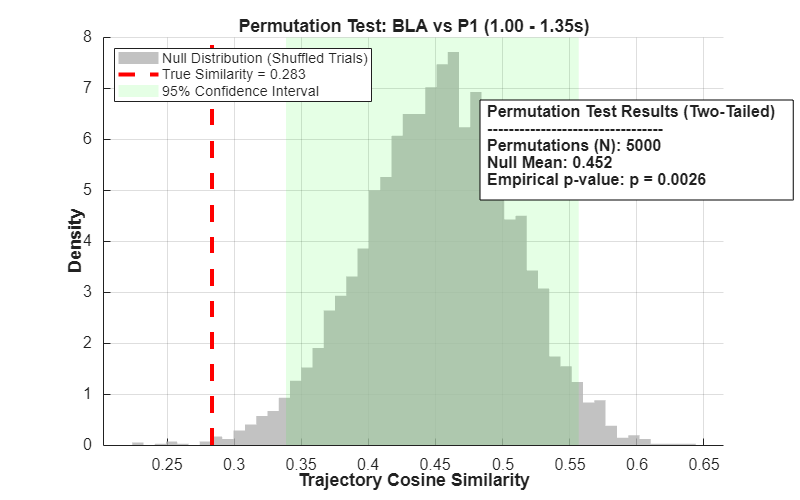


%% 1. Calculate the TRUE Trajectory Similarity (The Baseline)
for s = 1:num_subjs
    % Extract LOSO decoder and mean for this specific subject
    master_W = dpca_models.(m_name).loso(s).W(:, num_comps_sim);
    mu_s     = dpca_models.(m_name).loso(s).mu;
    
    % Average true trials
    data_A = mean(data_all_conds.(cond_A){s}, 3, 'omitnan');
    data_B = mean(data_all_conds.(cond_B){s}, 3, 'omitnan');
    
    if isempty(data_A) || isempty(data_B), continue; end
    
    % Project into shared LOSO space
    proj_A = master_W' * (data_A - mu_s);
    proj_B = master_W' * (data_B - mu_s);
    
    % Extract window trajectories
    traj_A = proj_A(idx_win);
    traj_B = proj_B(idx_win);
    
    % Remove NaNs (in case a condition drops out early)
    valid = ~isnan(traj_A) & ~isnan(traj_B);
    traj_A = traj_A(valid);
    traj_B = traj_B(valid);
    
    % TRUE Cosine Similarity of 1D Trajectories
    if length(traj_A) > 1
        true_sim_subj(s) = dot(traj_A, traj_B) / (norm(traj_A) * norm(traj_B));
    else
        true_sim_subj(s) = NaN;
    end
end
true_mean_sim = mean(true_sim_subj, 'omitnan');

%% 2. Calculate the NULL Distribution (Trial Shuffling)
for p = 1:n_perms
    null_sim_subj = zeros(num_subjs, 1);
    
    for s = 1:num_subjs
        master_W = dpca_models.(m_name).loso(s).W(:, num_comps_sim);
        mu_s     = dpca_models.(m_name).loso(s).mu;
        
        % Extract single trials
        trials_A = data_all_conds.(cond_A){s};
        trials_B = data_all_conds.(cond_B){s};
        
        nA = size(trials_A, 3);
        nB = size(trials_B, 3);
        
        % Pool all trials together and Shuffle
        all_trials = cat(3, trials_A, trials_B);
        total_trials = nA + nB;
        shuffled_idx = randperm(total_trials);
        
        % Calculate "Pseudo-Averages"
        pseudo_A = mean(all_trials(:, :, shuffled_idx(1:nA)), 3, 'omitnan');
        pseudo_B = mean(all_trials(:, :, shuffled_idx(nA+1:end)), 3, 'omitnan');
        
        % Project into the EXACT same fixed dPCA space
        proj_pA = master_W' * (pseudo_A - mu_s);
        proj_pB = master_W' * (pseudo_B - mu_s);
        
        traj_pA = proj_pA(idx_win);
        traj_pB = proj_pB(idx_win);
        
        valid = ~isnan(traj_pA) & ~isnan(traj_pB);
        traj_pA = traj_pA(valid);
        traj_pB = traj_pB(valid);
        
        % NULL Cosine Similarity
        if length(traj_pA) > 1
            null_sim_subj(s) = dot(traj_pA, traj_pB) / (norm(traj_pA) * norm(traj_pB));
        else
            null_sim_subj(s) = NaN;
        end
    end
    % Store the mean pseudo-similarity for this permutation
    null_distribution_means(p) = mean(null_sim_subj, 'omitnan');
end

%% 3. Calculate Two-Tailed P-Value and Plot Histogram
% Center of the null distribution
null_mean = mean(null_distribution_means, 'omitnan');

% Absolute distances from the center
true_distance = abs(true_mean_sim - null_mean);
null_distances = abs(null_distribution_means - null_mean);

% TWO-TAILED P-VALUE: How many shuffled sims were further from the center?
p_value = sum(null_distances >= true_distance) / n_perms;

if p_value == 0
    p_str = sprintf('p < %.4f', 1/n_perms);
else
    p_str = sprintf('p = %.4f', p_value);
end

% --- PLOTTING ---
figure('Position', [200, 200, 800, 500], 'Name', 'Permutation Test');
hold on;

% Plot the Null Distribution
histogram(null_distribution_means, 50, 'Normalization', 'pdf', ...
    'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'none', 'FaceAlpha', 0.8);

y_lims = ylim;
% Plot the True Value
line([true_mean_sim, true_mean_sim], y_lims, 'Color', 'r', 'LineWidth', 3, 'LineStyle', '--');

% Calculate the 95% Confidence Bounds (Using 2.5 and 97.5)
ci_lower = prctile(null_distribution_means, 2.5);
ci_upper = prctile(null_distribution_means, 97.5);
patch([ci_lower, ci_upper, ci_upper, ci_lower], [y_lims(1) y_lims(1) y_lims(2) y_lims(2)], ...
    'g', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', '95% CI (Noise Ceiling)');

hold off;
title(sprintf('Permutation Test: %s vs %s (%.2f - %.2fs)', cond_A, cond_B, test_window(1), test_window(2)), ...
    'FontSize', 18, 'FontWeight', 'bold');
xlabel('Trajectory Cosine Similarity', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Density', 'FontSize', 14, 'FontWeight', 'bold');
grid on; set(gca, 'FontSize', 12);

legend({'Null Distribution (Shuffled Trials)', sprintf('True Similarity = %.3f', true_mean_sim), ...
    '95% Confidence Interval'}, 'Location', 'northwest');

% Annotation Box
stat_str = {
    'Permutation Test Results (Two-Tailed)',
    '---------------------------------',
    sprintf('Permutations (N): %d', n_perms),
    sprintf('Null Mean: %.3f', null_mean),
    sprintf('Empirical p-value: %s', p_str)
};
annotation('textbox', [0.60 0.65 0.28 0.15], 'String', stat_str, ...
    'FitBoxToText', 'on', 'BackgroundColor', 'w', 'EdgeColor', 'k', ...
    'FontSize', 12, 'FontWeight', 'bold', 'Interpreter', 'none');


disp('Permutation test complete.');

Permutation test complete.



disp('Permutation test complete.');

Permutation test complete.


## 6.1: Temporal Uncertainty

%% 6.0 False Positive Validation: Permutation Test (Latent Trajectories)
disp('Running False Positive Permutation Test (Latent Trajectory Shuffling)...');

Running False Positive Permutation Test (Latent Trajectory Shuffling)...


warning('off', 'all');

% --- Test Parameters ---
cond_A = 'P1';
cond_B = 'P2_500';
m_name = 'Temp';             % Which dPCA space to use (MS, Temp, Stim)
test_window = [1.00, 1.35];  % The exact time window to test
n_perms = 5000;              % Increased to 5000 for smooth, reliable p-values
num_comps_sim = 1;           % Test dPC1

num_subjs = length(data_all_conds.(cond_A));
idx_win = find(time_ms_eeg >= test_window(1) & time_ms_eeg <= test_window(2));

% Arrays to hold results
null_distribution_means = zeros(n_perms, 1);
true_sim_subj = zeros(num_subjs, 1);

fprintf('Testing %s vs %s in window [%.2f - %.2fs]\n', cond_A, cond_B, test_window(1), test_window(2));

Testing P1 vs P2_500 in window [1.00 - 1.35s]


fprintf('Running %d permutations. This will take a moment...\n', n_perms);

Running 5000 permutations. This will take a moment...


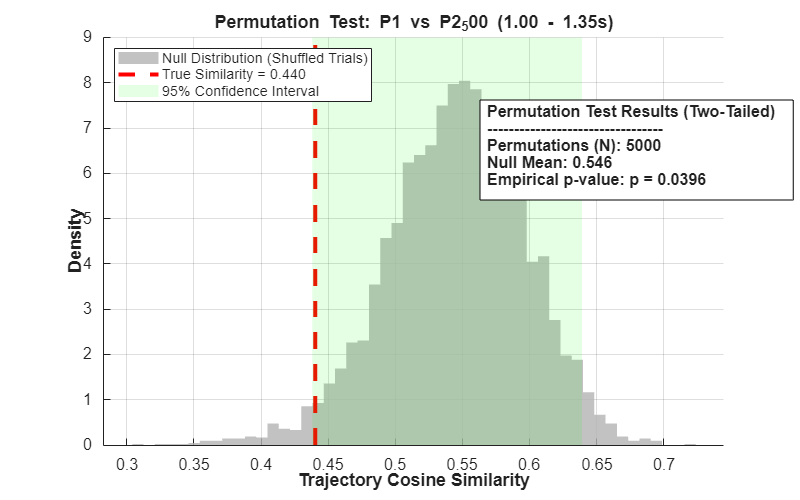


%% 1. Calculate the TRUE Trajectory Similarity (The Baseline)
for s = 1:num_subjs
    % Extract LOSO decoder and mean for this specific subject
    master_W = dpca_models.(m_name).loso(s).W(:, num_comps_sim);
    mu_s     = dpca_models.(m_name).loso(s).mu;
    
    % Average true trials
    data_A = mean(data_all_conds.(cond_A){s}, 3, 'omitnan');
    data_B = mean(data_all_conds.(cond_B){s}, 3, 'omitnan');
    
    if isempty(data_A) || isempty(data_B), continue; end
    
    % Project into shared LOSO space
    proj_A = master_W' * (data_A - mu_s);
    proj_B = master_W' * (data_B - mu_s);
    
    % Extract window trajectories
    traj_A = proj_A(idx_win);
    traj_B = proj_B(idx_win);
    
    % Remove NaNs (in case a condition drops out early)
    valid = ~isnan(traj_A) & ~isnan(traj_B);
    traj_A = traj_A(valid);
    traj_B = traj_B(valid);
    
    % TRUE Cosine Similarity of 1D Trajectories
    if length(traj_A) > 1
        true_sim_subj(s) = dot(traj_A, traj_B) / (norm(traj_A) * norm(traj_B));
    else
        true_sim_subj(s) = NaN;
    end
end
true_mean_sim = mean(true_sim_subj, 'omitnan');

%% 2. Calculate the NULL Distribution (Trial Shuffling)
for p = 1:n_perms
    null_sim_subj = zeros(num_subjs, 1);
    
    for s = 1:num_subjs
        master_W = dpca_models.(m_name).loso(s).W(:, num_comps_sim);
        mu_s     = dpca_models.(m_name).loso(s).mu;
        
        % Extract single trials
        trials_A = data_all_conds.(cond_A){s};
        trials_B = data_all_conds.(cond_B){s};
        
        nA = size(trials_A, 3);
        nB = size(trials_B, 3);
        
        % Pool all trials together and Shuffle
        all_trials = cat(3, trials_A, trials_B);
        total_trials = nA + nB;
        shuffled_idx = randperm(total_trials);
        
        % Calculate "Pseudo-Averages"
        pseudo_A = mean(all_trials(:, :, shuffled_idx(1:nA)), 3, 'omitnan');
        pseudo_B = mean(all_trials(:, :, shuffled_idx(nA+1:end)), 3, 'omitnan');
        
        % Project into the EXACT same fixed dPCA space
        proj_pA = master_W' * (pseudo_A - mu_s);
        proj_pB = master_W' * (pseudo_B - mu_s);
        
        traj_pA = proj_pA(idx_win);
        traj_pB = proj_pB(idx_win);
        
        valid = ~isnan(traj_pA) & ~isnan(traj_pB);
        traj_pA = traj_pA(valid);
        traj_pB = traj_pB(valid);
        
        % NULL Cosine Similarity
        if length(traj_pA) > 1
            null_sim_subj(s) = dot(traj_pA, traj_pB) / (norm(traj_pA) * norm(traj_pB));
        else
            null_sim_subj(s) = NaN;
        end
    end
    % Store the mean pseudo-similarity for this permutation
    null_distribution_means(p) = mean(null_sim_subj, 'omitnan');
end

%% 3. Calculate Two-Tailed P-Value and Plot Histogram
% Center of the null distribution
null_mean = mean(null_distribution_means, 'omitnan');

% Absolute distances from the center
true_distance = abs(true_mean_sim - null_mean);
null_distances = abs(null_distribution_means - null_mean);

% TWO-TAILED P-VALUE: How many shuffled sims were further from the center?
p_value = sum(null_distances >= true_distance) / n_perms;

if p_value == 0
    p_str = sprintf('p < %.4f', 1/n_perms);
else
    p_str = sprintf('p = %.4f', p_value);
end

% --- PLOTTING ---
figure('Position', [200, 200, 800, 500], 'Name', 'Permutation Test');
hold on;

% Plot the Null Distribution
histogram(null_distribution_means, 50, 'Normalization', 'pdf', ...
    'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'none', 'FaceAlpha', 0.8);

y_lims = ylim;
% Plot the True Value
line([true_mean_sim, true_mean_sim], y_lims, 'Color', 'r', 'LineWidth', 3, 'LineStyle', '--');

% Calculate the 95% Confidence Bounds (Using 2.5 and 97.5)
ci_lower = prctile(null_distribution_means, 2.5);
ci_upper = prctile(null_distribution_means, 97.5);
patch([ci_lower, ci_upper, ci_upper, ci_lower], [y_lims(1) y_lims(1) y_lims(2) y_lims(2)], ...
    'g', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', '95% CI (Noise Ceiling)');

hold off;
title(sprintf('Permutation Test: %s vs %s (%.2f - %.2fs)', cond_A, cond_B, test_window(1), test_window(2)), ...
    'FontSize', 18, 'FontWeight', 'bold');
xlabel('Trajectory Cosine Similarity', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Density', 'FontSize', 14, 'FontWeight', 'bold');
grid on; set(gca, 'FontSize', 12);

legend({'Null Distribution (Shuffled Trials)', sprintf('True Similarity = %.3f', true_mean_sim), ...
    '95% Confidence Interval'}, 'Location', 'northwest');

% Annotation Box
stat_str = {
    'Permutation Test Results (Two-Tailed)',
    '---------------------------------',
    sprintf('Permutations (N): %d', n_perms),
    sprintf('Null Mean: %.3f', null_mean),
    sprintf('Empirical p-value: %s', p_str)
};
annotation('textbox', [0.60 0.65 0.28 0.15], 'String', stat_str, ...
    'FitBoxToText', 'on', 'BackgroundColor', 'w', 'EdgeColor', 'k', ...
    'FontSize', 12, 'FontWeight', 'bold', 'Interpreter', 'none');


disp('Permutation test complete.');

Permutation test complete.


## 6.2: Stimulus Uncertainty

%% 6.0 False Positive Validation: Permutation Test (Latent Trajectories)
disp('Running False Positive Permutation Test (Latent Trajectory Shuffling)...');

Running False Positive Permutation Test (Latent Trajectory Shuffling)...


warning('off', 'all');

% --- Test Parameters ---
cond_A = 'P1';
cond_B = 'P3_missing';
m_name = 'Stim';             % Which dPCA space to use (MS, Temp, Stim)
test_window = [1.00, 1.35];  % The exact time window to test
n_perms = 5000;              % Increased to 5000 for smooth, reliable p-values
num_comps_sim = 1;           % Test dPC1

num_subjs = length(data_all_conds.(cond_A));
idx_win = find(time_ms_eeg >= test_window(1) & time_ms_eeg <= test_window(2));

% Arrays to hold results
null_distribution_means = zeros(n_perms, 1);
true_sim_subj = zeros(num_subjs, 1);

fprintf('Testing %s vs %s in window [%.2f - %.2fs]\n', cond_A, cond_B, test_window(1), test_window(2));

Testing P1 vs P3_missing in window [1.00 - 1.35s]


fprintf('Running %d permutations. This will take a moment...\n', n_perms);

Running 5000 permutations. This will take a moment...


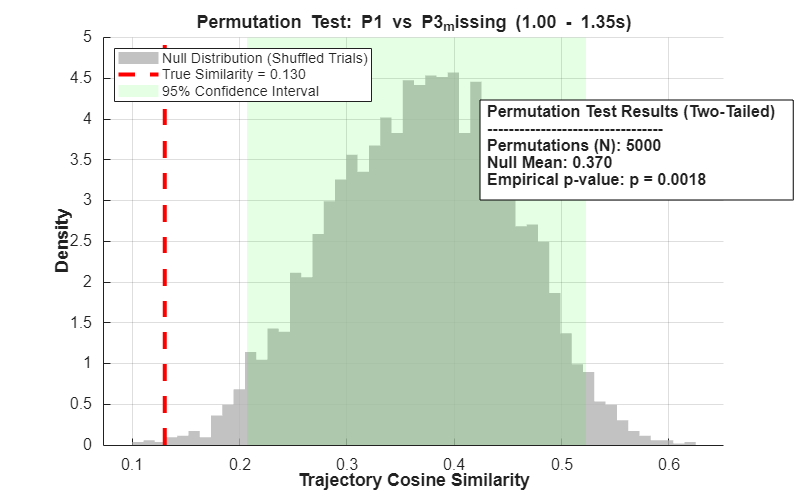


%% 1. Calculate the TRUE Trajectory Similarity (The Baseline)
for s = 1:num_subjs
    % Extract LOSO decoder and mean for this specific subject
    master_W = dpca_models.(m_name).loso(s).W(:, num_comps_sim);
    mu_s     = dpca_models.(m_name).loso(s).mu;
    
    % Average true trials
    data_A = mean(data_all_conds.(cond_A){s}, 3, 'omitnan');
    data_B = mean(data_all_conds.(cond_B){s}, 3, 'omitnan');
    
    if isempty(data_A) || isempty(data_B), continue; end
    
    % Project into shared LOSO space
    proj_A = master_W' * (data_A - mu_s);
    proj_B = master_W' * (data_B - mu_s);
    
    % Extract window trajectories
    traj_A = proj_A(idx_win);
    traj_B = proj_B(idx_win);
    
    % Remove NaNs (in case a condition drops out early)
    valid = ~isnan(traj_A) & ~isnan(traj_B);
    traj_A = traj_A(valid);
    traj_B = traj_B(valid);
    
    % TRUE Cosine Similarity of 1D Trajectories
    if length(traj_A) > 1
        true_sim_subj(s) = dot(traj_A, traj_B) / (norm(traj_A) * norm(traj_B));
    else
        true_sim_subj(s) = NaN;
    end
end
true_mean_sim = mean(true_sim_subj, 'omitnan');

%% 2. Calculate the NULL Distribution (Trial Shuffling)
for p = 1:n_perms
    null_sim_subj = zeros(num_subjs, 1);
    
    for s = 1:num_subjs
        master_W = dpca_models.(m_name).loso(s).W(:, num_comps_sim);
        mu_s     = dpca_models.(m_name).loso(s).mu;
        
        % Extract single trials
        trials_A = data_all_conds.(cond_A){s};
        trials_B = data_all_conds.(cond_B){s};
        
        nA = size(trials_A, 3);
        nB = size(trials_B, 3);
        
        % Pool all trials together and Shuffle
        all_trials = cat(3, trials_A, trials_B);
        total_trials = nA + nB;
        shuffled_idx = randperm(total_trials);
        
        % Calculate "Pseudo-Averages"
        pseudo_A = mean(all_trials(:, :, shuffled_idx(1:nA)), 3, 'omitnan');
        pseudo_B = mean(all_trials(:, :, shuffled_idx(nA+1:end)), 3, 'omitnan');
        
        % Project into the EXACT same fixed dPCA space
        proj_pA = master_W' * (pseudo_A - mu_s);
        proj_pB = master_W' * (pseudo_B - mu_s);
        
        traj_pA = proj_pA(idx_win);
        traj_pB = proj_pB(idx_win);
        
        valid = ~isnan(traj_pA) & ~isnan(traj_pB);
        traj_pA = traj_pA(valid);
        traj_pB = traj_pB(valid);
        
        % NULL Cosine Similarity
        if length(traj_pA) > 1
            null_sim_subj(s) = dot(traj_pA, traj_pB) / (norm(traj_pA) * norm(traj_pB));
        else
            null_sim_subj(s) = NaN;
        end
    end
    % Store the mean pseudo-similarity for this permutation
    null_distribution_means(p) = mean(null_sim_subj, 'omitnan');
end

%% 3. Calculate Two-Tailed P-Value and Plot Histogram
% Center of the null distribution
null_mean = mean(null_distribution_means, 'omitnan');

% Absolute distances from the center
true_distance = abs(true_mean_sim - null_mean);
null_distances = abs(null_distribution_means - null_mean);

% TWO-TAILED P-VALUE: How many shuffled sims were further from the center?
p_value = sum(null_distances >= true_distance) / n_perms;

if p_value == 0
    p_str = sprintf('p < %.4f', 1/n_perms);
else
    p_str = sprintf('p = %.4f', p_value);
end

% --- PLOTTING ---
figure('Position', [200, 200, 800, 500], 'Name', 'Permutation Test');
hold on;

% Plot the Null Distribution
histogram(null_distribution_means, 50, 'Normalization', 'pdf', ...
    'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'none', 'FaceAlpha', 0.8);

y_lims = ylim;
% Plot the True Value
line([true_mean_sim, true_mean_sim], y_lims, 'Color', 'r', 'LineWidth', 3, 'LineStyle', '--');

% Calculate the 95% Confidence Bounds (Using 2.5 and 97.5)
ci_lower = prctile(null_distribution_means, 2.5);
ci_upper = prctile(null_distribution_means, 97.5);
patch([ci_lower, ci_upper, ci_upper, ci_lower], [y_lims(1) y_lims(1) y_lims(2) y_lims(2)], ...
    'g', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', '95% CI (Noise Ceiling)');

hold off;
title(sprintf('Permutation Test: %s vs %s (%.2f - %.2fs)', cond_A, cond_B, test_window(1), test_window(2)), ...
    'FontSize', 18, 'FontWeight', 'bold');
xlabel('Trajectory Cosine Similarity', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Density', 'FontSize', 14, 'FontWeight', 'bold');
grid on; set(gca, 'FontSize', 12);

legend({'Null Distribution (Shuffled Trials)', sprintf('True Similarity = %.3f', true_mean_sim), ...
    '95% Confidence Interval'}, 'Location', 'northwest');

% Annotation Box
stat_str = {
    'Permutation Test Results (Two-Tailed)',
    '---------------------------------',
    sprintf('Permutations (N): %d', n_perms),
    sprintf('Null Mean: %.3f', null_mean),
    sprintf('Empirical p-value: %s', p_str)
};
annotation('textbox', [0.60 0.65 0.28 0.15], 'String', stat_str, ...
    'FitBoxToText', 'on', 'BackgroundColor', 'w', 'EdgeColor', 'k', ...
    'FontSize', 12, 'FontWeight', 'bold', 'Interpreter', 'none');


disp('Permutation test complete.');

Permutation test complete.
